# Vehicle Motion Planning and Control

The main vehicle motion planning and control block diagram is shown below. For the vehicles using the Stanley Lateral Controller, the Local Trajectory Planner doesn't output the coordinates of the next waypoints but the pose and the orientation of the closest waypoint on the path that is perpendicular to the front axle of the vehicle. The output of the Stanley Lateral Control is the steering angle command, which is same as the Pure Pursuit Lateral Controller. Therefore the superclass `Local Trajector Planner` is shown below but in the implementation the subclass `Stanley_RefPoseGenerator.m` or `PurePursuit_WPGenerator.m` is used.

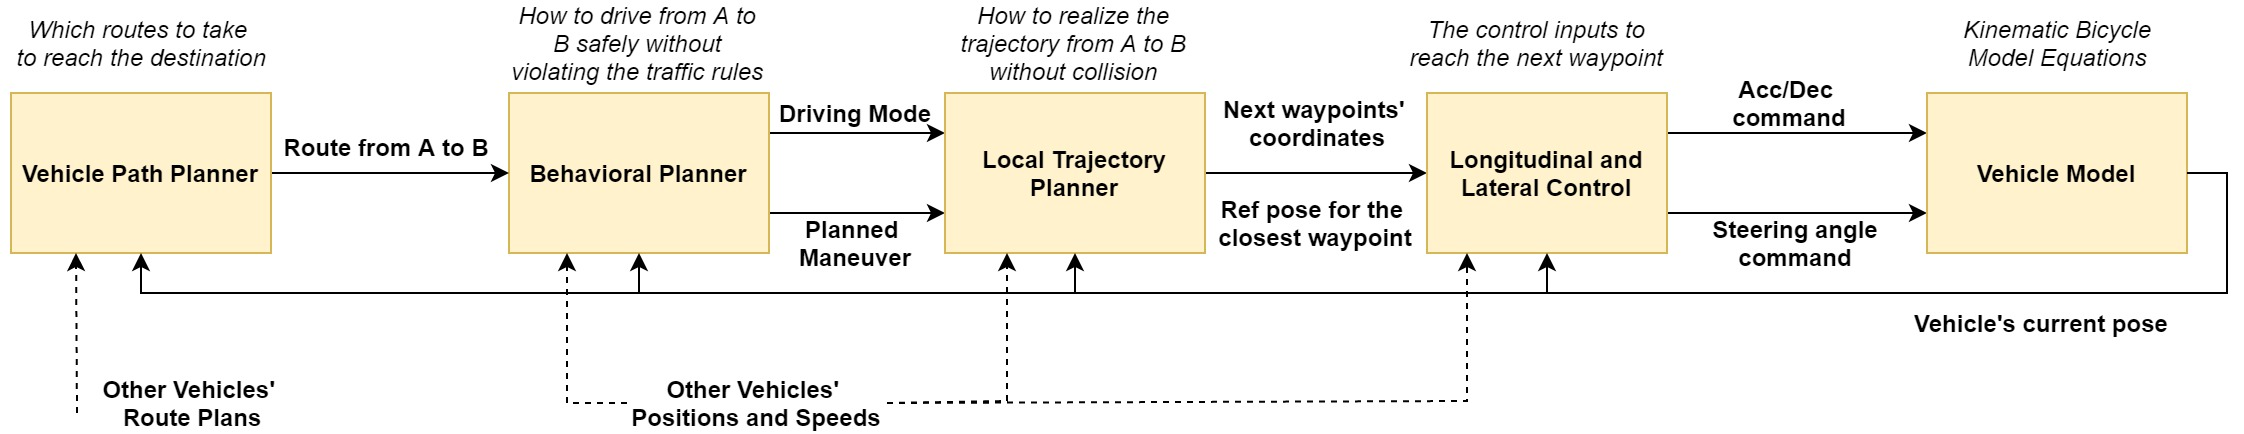

This figure illustrates the motion planning for the vehicle from the highest level on the left until the vehicle model. Note that it doesn't show the V2V Data influx coming to the Vehicle Path Planner or the Sensors Block output. The structure in MOBATSim therefore, is not exactly the same but this abstraction defines how an autonomous vehicle in MOBATSim reaches the destination node from the starting node. One of the ideas behind MOBATSim's development is the modularity and decoupling between components. So the motion planning explained in this document is still valid even when other vehicles come into play. The protocols for interactions with other vehicles, mechanisms to cope with their unexpected behavior,  and their actions shall be explained in another chapter.

# I- Vehicle Path Planner

The abstract superclass **Vehicle Path Planner** has two subclasses for implementation. `VehiclePathPlanner_shortestPathFinder.m `takes the digraph structure of the map as an input and outputs the shortest path based on the length of the edges between nodes. It doesn't take the other vehicles and their planned paths into account, therefore, it always outputs the shortest possible path based solely on the sum of the distance.

The `VehiclePathPlanner_Astar.m` subclass is more commonly used and it takes an extra input which is the shared data by other autonomous vehicles. At the beginning of the simulation, all the vehicles make a path plan based on a set of nodes and edges. In this plan, they also calculate their estimated time of arrival to each waypoint. When vehicles make the whole plan, which is a discrete set of waypoints to be visited in order to reach the destination waypoint, they also share it with other vehicles if they have the V2V connection. This enables the replanning of the path for some of the vehicles in certain circumstances, such as, if there is a short path which is occupied by a slower vehicle and a longer path that has faster vehicles on it, depending of the estimated time of arrival, the vehicle can replan its path and choose the longer but faster route. This reduces the traffic congestion if faster vehicles can avoid following slower vehicles on single lane roads.

The code snippet above can be seen in the superclass with the set of abstract methods that are defined. These abstract methods have to be implemented by any subclass, as it requires some common procedures to ensure compatibility.

# II- Behavioral Planner

At the moment there are two separate files for the Behavioral Planners. One of them is used for most of the vehicles and it has the name `VehicleDrivingMode.m`. The second vehicle has the lane-changing maneuver implemented, so it has a few different functions and it is only implemented in Vehicle 2 at the moment (`VehicleDrivingMode_Ego.m`).

# III- Local Trajectory Planner

The local trajectory planner is the superclass of two classes. This section covers mostly the theory and the implementation of the superclass functions. The details and differences between Lateral Stanley Controller and Pure Pursuit are mentioned after introducing the Frenet Coordinate System, which is a common part in both lateral controllers.

## Frenet Coordinate System

Frenet coordinate system is a coordinate system that is relevant to the road specifications that the vehicle is currently traversing. It is uses the road structure that MOBATSim is based on, which consists of straight and curved roads. At each road segment, which is referred to as **route** in MOBATSim, the vehicle starts from the s=0 coordinate and then moves to the s=s_endPoint. The curved road also uses the angles around the rotation point of the curve, as each arc has a constant curvature. 

One of the most important uses for the Frenet Coordinate System is that allows the vehicles to define some of the lateral maneuvers such as the lane-changing and overtaking maneuvers regardless of the road structure. Rather than creating separate functions for straight and curved roads according to their position on the global x-y coordinate system, the maneuvers are going to be defined in the Frenet Frame. However, how these maneuvers are defined will be explained after the transformations.

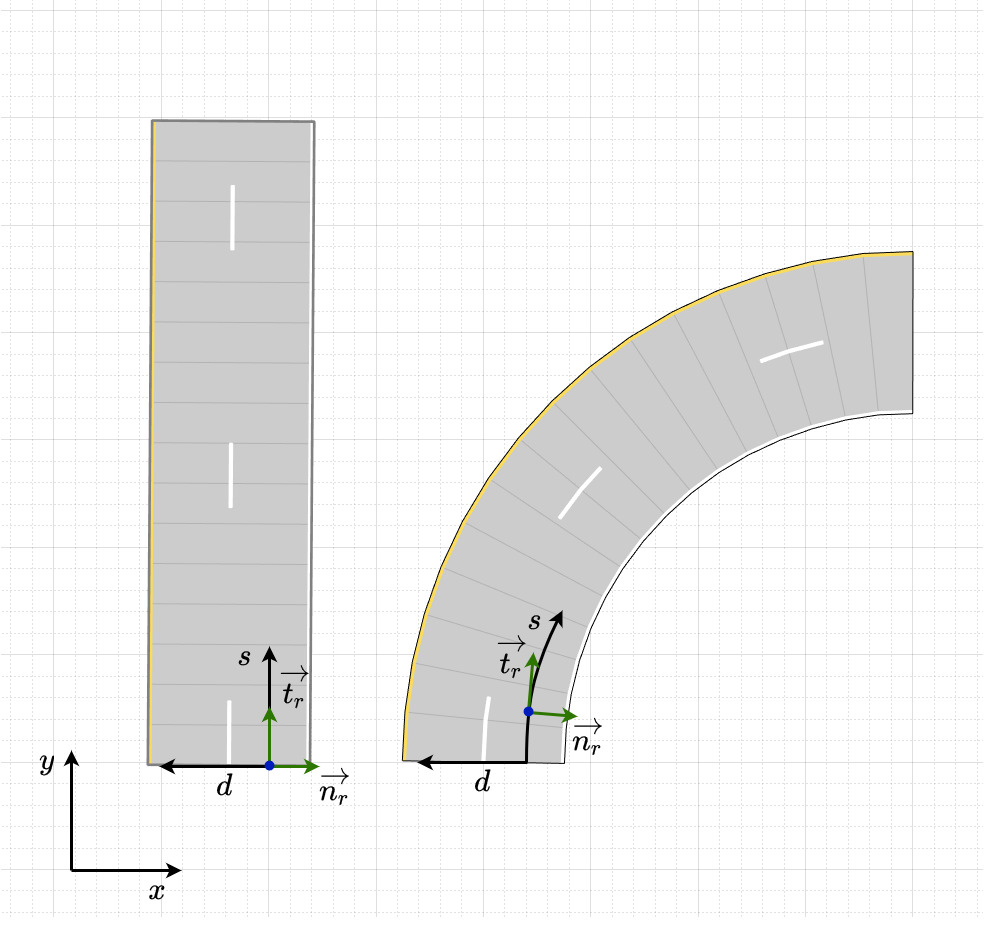

In this section the coordinate transformations from the global cartesian system to the Frenet Frame and then back to Cartesian Coordinates to create required output for the lateral controllers will be explained. So let's start with the straight road.

### Straight Road - Cartesian to Frenet Coordinates

The longitudinal coordinate s starts from the starting point and goes to the end point of the route. On a single lane road shown below, the s value of the end point is the length of the vector. The reference for the road center line is always d=0 and any deviation to the left is positive d direction and the right-side is negative d direction. The car in the example figure is not exactly on the road and its orientation phi is also not the same as the road orientation theta. Therefore the vehicle tries to make its lateral displacement d value zero by steering left. The projection of the vehicle's position on the AB vector gives the traversed part of the line. This value is obtained by the dot product of the unit vector of AB and AV. In a similar fashion, the lateral displacement can be calculated by multiplying the vehicle's displacement vector with the normal vector of the road, which is always perpendicular to the unit vector of AB and points left.

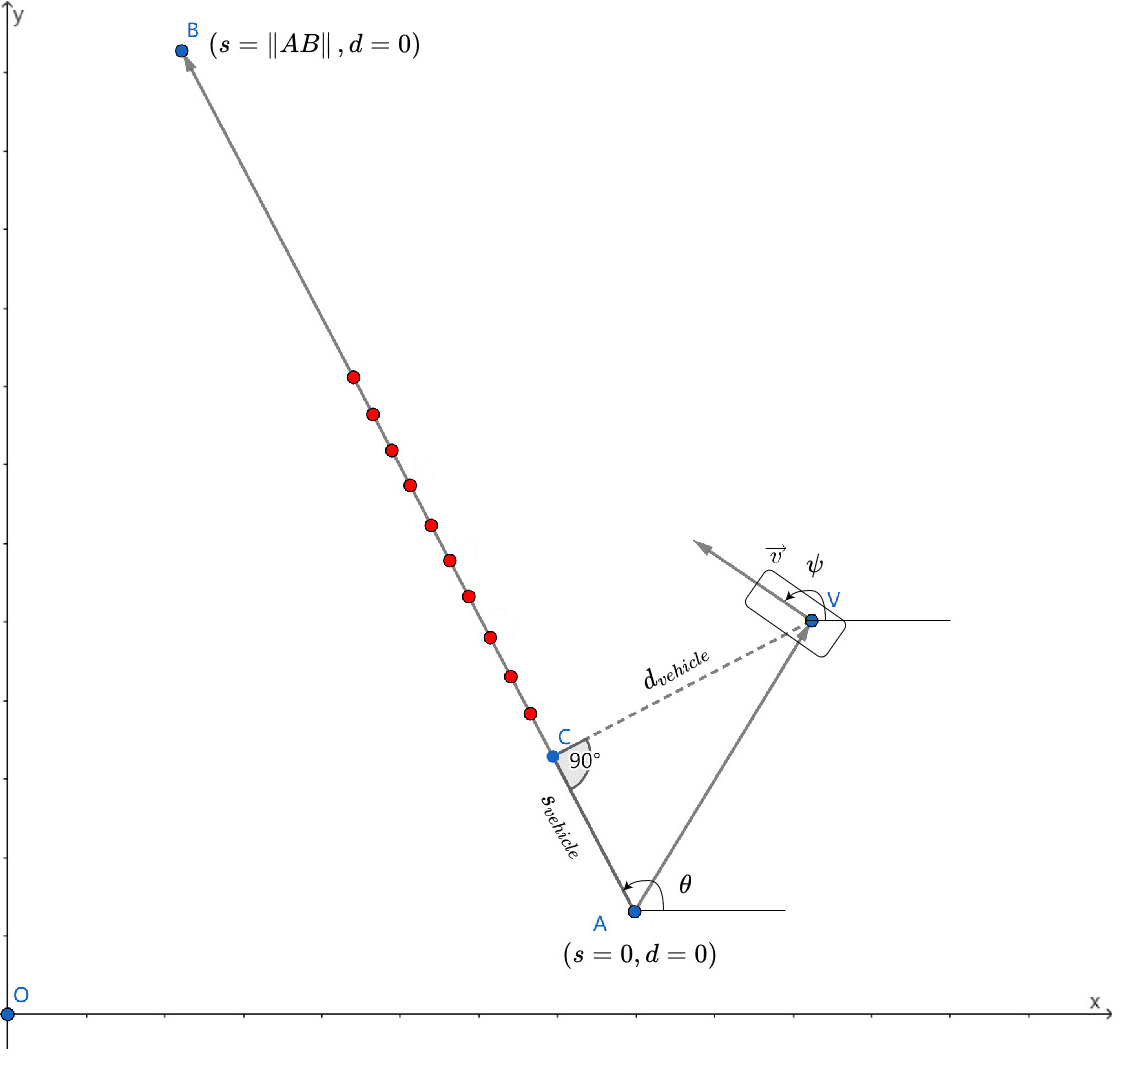

where,


$$A:\textrm{Starting}\;\textrm{point}\;\textrm{of}\;\textrm{the}\;\textrm{current}\;\textrm{route}\;\left(s=0\right)$$



$$B:\textrm{Destination}\;\textrm{point}\;\textrm{of}\;\textrm{the}\;\textrm{current}\;\textrm{route}\left(s=\left\|\textrm{AB}\right\|\right)$$



$$C:\textrm{Projection}\;\textrm{of}\;\textrm{the}\;\textrm{vehicle}\;\textrm{vector}\;\textrm{to}\;\textrm{the}\;\textrm{route}\;\left(\left\|\textrm{AC}\right\|=s_{\textrm{vehicle}} \;\textrm{and}\;\left\|\textrm{CV}\right\|=d_{\textrm{vehicle}} \right)$$


$\theta :\textrm{Orientation}\;\textrm{of}\;\textrm{the}\;\textrm{straight}\;\textrm{route}$ (angle from the $x$ axis)


$$V:{\textrm{Vehicle}}^{\prime } s\;\textrm{current}\;\textrm{position}$$



$$\overrightarrow{v} :\textrm{Velocity}\;\textrm{vector}\;\textrm{of}\;\textrm{the}\;\textrm{vehicle}$$


$\phi :\textrm{Orientation}\;\textrm{of}\;\textrm{the}\;\textrm{vehicle}$ (angle from the $x$ axis)

$O$: Origin of the global cartesian coordinate system $\left(x,y\right)$

$\overrightarrow{wp_i}$: Reference waypoints (red circles) with $i =1,2,...,k$ calculated by $\overrightarrow{wp_i}=\overrightarrow{AC}+\Delta_i\cdot \overrightarrow{AB}$ , where $\Delta$ is a scalar distance value between the waypoints.

Here is another example below where the road is double lane. The right lane is always the d=0 reference and the left lane's d value is equal to 3.7 meters. This is the standard road geometry in MOBATSim, however it can be edited. In this example let's consider the road length to be 100 meters from A to B and then determine the values of the vehicles at the given state. Yellow vehicle is making a lane-changing manevuer by steering left, hence it is taking the left lane (d=3.7 line) as the reference. The purple vehicle is on the right lane and a little bit ahead, therefore it has a greater s value. The green vehicle is way ahead of the other vehicles, so it has the highest s value and also it is driving straight with d=3.7. Even though the green vehicle is also trying to reach the end of the road, here it suffices to reach s=100 with d=3.7 if the next road segment is also a double road. Hence, the waypoint reach trigger is not directly based on a point but an imaginary line that is perpendicular to the road flow direction and covers the d values other than d=0. 

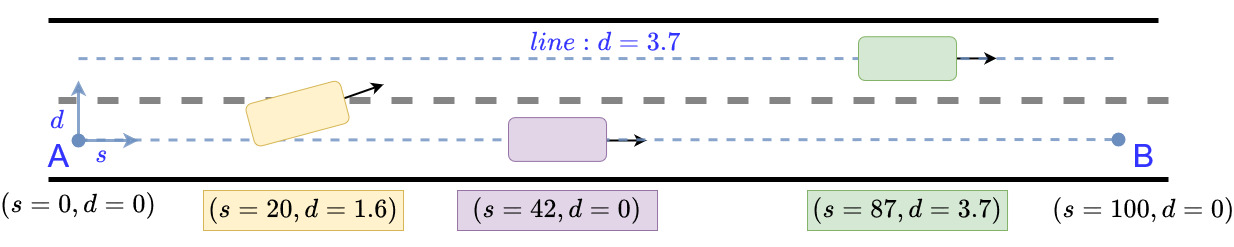

Here is a code snippet for calculating the s and d values on a straight road.

### Curved Road - Cartesian to Frenet Coordinates

Curved roads are based on arcs which have a constant radius (thereby a constant curvature) along an angle that sweeps from the starting point to the end point of the route segment. In the figure below, you can see three road segments with different radii, sweeping angles, and rotation centers. Further updates involving support for Bezier curves and other structures are planned but at the moment they are approximated by a number of arcs sequentially. The Frenet coordinate system for arcs also follow the same coordinates, namely "s" and "d" but the calculation is not as straightforward as the in the straight road segments.

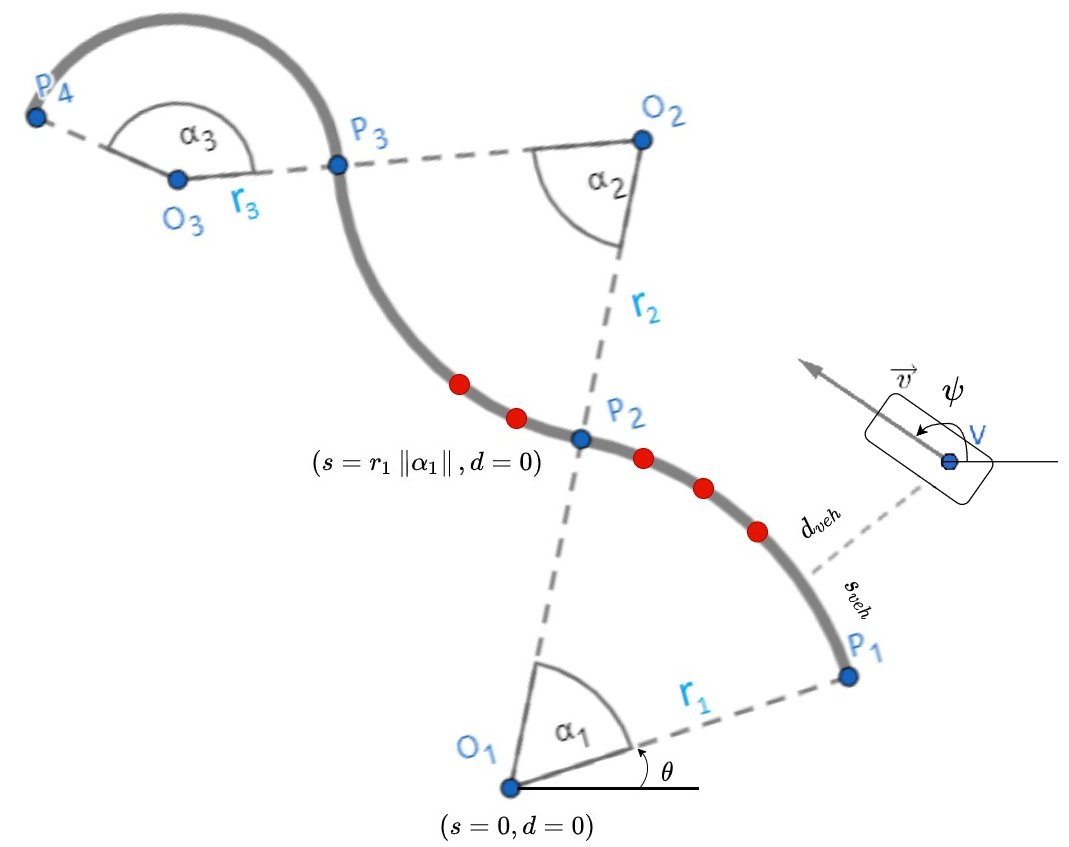

The length of an arc is given by:  $s_i =r_i \;\alpha_i$ where $r_i$ is the radius of the road segment i and $\alpha_i$ the sweeping angle in radians. The next reference waypoints are generated in a similar fashion as the straight road but with angle:

$\overrightarrow{wp_i}=\overrightarrow{OO_{i}}+\cdot\overrightarrow{r_i}[cos(\theta_i+\Delta_i) \ sin(\theta_i+\Delta_i)]$ for $ i=1,2,...,k$.

Therefore it is imperative to calculate the vehicle's position according to the rotation center $O$ to be able determine the projection of vehicle's traversion over the arc. Note that the road segment "s" values change relatively. For the road segment 1, the "s" value of point P2 is a positive definite number, whereas for road segment 2, since it starts with point P2, the value is equal to s=0. These discrete jumps are via checkWaypointReached functions with an $\epsilon$ tolerance value.

The two code snippets shown above are actually combined into one function called Cartesian2Frenet and an if statement separates the straight road from the curved one according to the radian value, which is zero for straight roads.

The information about the counterclockwise or the clockwise turning of the path is necessary for avoiding ambiguitiy. The same vehicle position on the same curved road with a slight deviation from the centerline of the road may have differently signed "d" values according to their rotation direction as seen in the figure below.

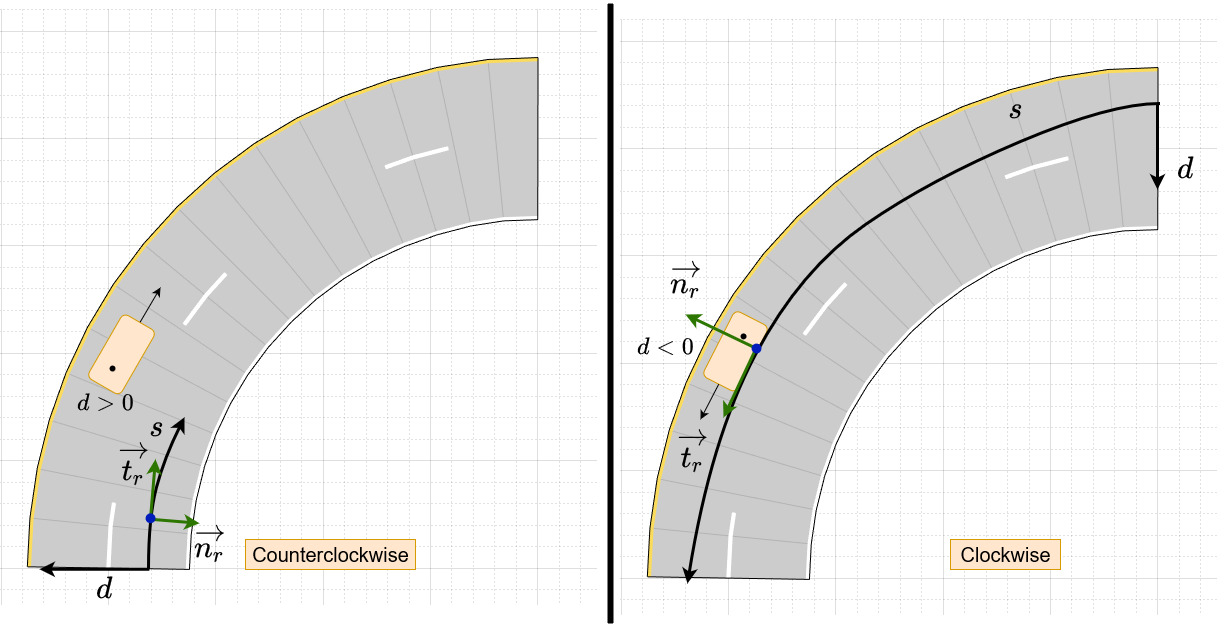

The conversion from Frenet to Cartesian of the coordinates will be explained in a later Section according to the workflow in MOBATSim. The main reason for converting Cartesian Coordinates to Frenet was to calculate trajectories that are invariant to the road structures. One of the most important trajectories to generate is the trajectory that realizes the lane-changing maneuver. Therefore, in the next section, the lane-changing maneuver is going to be explained in Frenet Coordinates that are obtained by the Cartesian2Frenet function above.

## Lane-Changing Maneuver

The lane-changing maneuver is an option for a vehicle if all the following propositions are true (i) the ego vehicle travels behind a significantly slower vehicle, (ii) the road is a double lane, (iii) there is enough distance ahead to complete the lane-changing and the road ahead is still double lane, (iv) the left lane is clear for the maneuver.

These conditions are checked by the behavioral layer's supervisory logic, as it wouldn't be meaningful to try to calculate a lane-changing trajectory (which is computationally more expensive than checking logical propositions) before the necessary conditions are met. Therefore the decision for lane changing is realized by the **Behavioral Planner Block** as shown in the code snippet below:

The first check is a simple one to avoid expensive calculations in every loop. If a vehicle is detected, the `switch_decision` function returns a discrete value corresponding to the command, which is captured by the `laneChange` variable.

Once the lane changing is allowed, this command is used as the output command that is required as an input for the local trajectory planner block.

The input signal changeLane is checked along with the laneChangingPoints (the code snippet below is only implemented in Pure Pursuit at the moment). The reason is that, the trajectory generation shouldn't happen at every sample time but when the changeLane signal is first received. Once it is received, the laneChangingPoints are generated and are non-empty. When the current maneuver is completed, they have to be reset to an empty set for the algorithm to be able to be used again when necessary.

The generation of the trajectory is explained in the next sections.

### Minimum Jerk Trajectory Generation

The trajectory generation on the 2D Frenet Frame is much easier than in Cartesian Coordinates and it is invariant to the direction, as the direction is already captured as the reference frame of the road segment. Therefore the lane-changing maneuver is only explained as on the straight road and it can be seen that the exact same algorithm provides also a minimum jerk trajectory on a curved road. The only difference might be about the maximum turn rate of the vehicle, as the vehicle is already following a curved road with a constant turn rate and then has to make an extra effort turn further for the lane-changing maneuver, which at some point might be hindered by the nonholonomic constraints of the vehicle defined by its maximum steering angle.

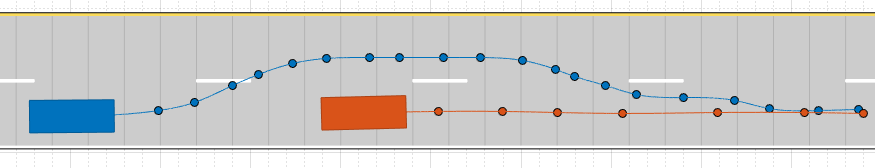

Suppose that Vehicle1 is followed by a faster vehicle, namely Vehicle2. After evaluating the lane-changing maneuver, let's suppose that Vehicle2 decides to change to left lane and then pass the slow Vehicle1, then return back to the right lane overtaking Vehicle1. The realize this lateral movement, we define a trajectory that minimizes the lateral jerk of the vehicle along the trajectory.

The structure of a minimum jerk trajectory in the lateral dimension consists of a polynomial of the sixth order (refer to Appendix I for more details on how to derive it) as shown below:


$$d(t)=a_0+a_1t+a_2t^2+a_3t^3+a_4t^4+a_5t^5$$


As we can see, we have to define six coefficients to determine the lateral trajectory of the vehicle. We define three boundary conditions for the beginning of the trajectory, and three conditions at the end of the trajectory thus having six linear equations, we can solve this using matrix operations in MATLAB.

Initial conditions would be the initial lateral displacement as the d value and zero for the lateral speed and acceleration as the vehicle is driving on its lane.


$$d(t_i=0)=d_i \ \rightarrow a_0=d_i
\\ \dot d(t_i=0)=0 \ \rightarrow a_1=0
\\ \ddot d(t_i=0)=0 \ \rightarrow a_2=0.$$


The first three coefficients are easy to solved with the initial conditions above and we can use them for the solution of the final conditions. The final conditions would be that the vehicle switches from the current lane to the desired lane and follows that lane without any further lateral speed or acceleration.


$$d(t_f)=d_f \ \rightarrow a_3t^3+a_4t^4+a_5t^5=d_f
\\ \dot d(t_f)=0 \ \rightarrow 3a_3t^2+4a_4t^3+5a_5t^4=0
\\ \ddot d(t_f)=0 \ \rightarrow 6a_3t+12a_4t^2+20a_5t^3=0$$


where $d_f$ is the lateral displacement of the desired lane from the initial lane. Using the above equations the variables $a_3 ,a_4 ,\textrm{and}\;a_5$ can be solved easily.

For example, if the vehicle is driving on the right lane and wants to switch to left lane in four seconds. The center of the left lane being 3.7 meters apart, the values become; ${t_i =0,\;d}_i =0$ and $t_f =4s,d_f =3\ldotp 7m$. By composing these six equations into a linear structure $\textrm{Ax}=B$, we can solve for the vector $x$ which is the column of all the $a$ coefficient values. Starting the time variable as $t=0:0\ldotp 02:t_f$ we can determine the points on the curve as a function of time as shown in the code snippet below:

s_current = 0;
Longitudinal_Speed = 10

Longitudinal_Speed = 10

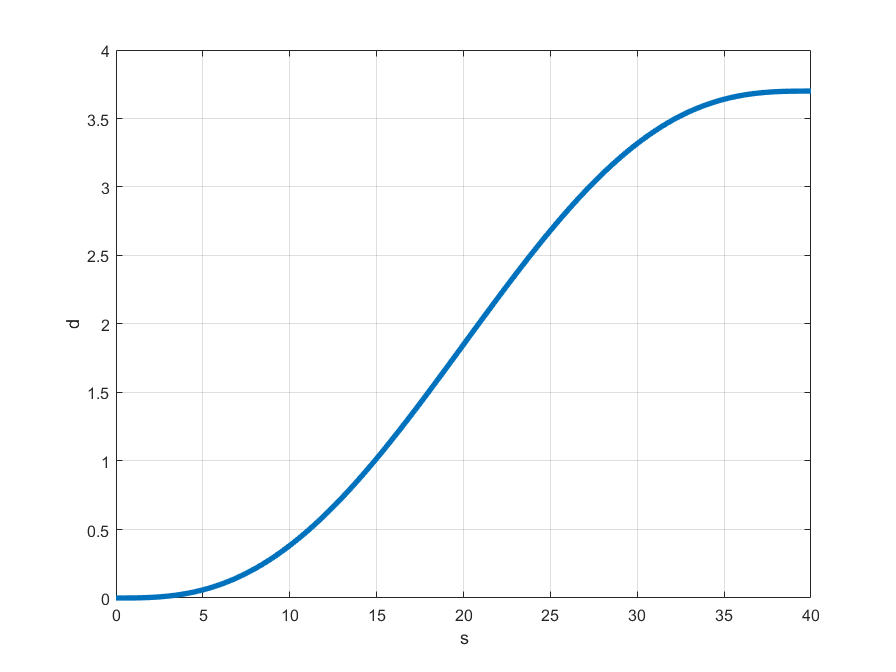

t_i = 0;
d_ti = [0; 0; 0]; % Initial lateral position, speed, acceleration

d_i =   [  1     t_i   t_i^2    t_i^3     t_i^4     t_i^5];
d_dot_i = [0     1   2*t_i  3*t_i^2   4*t_i^3   5*t_i^4];
d_ddot_i = [0     0     2    6*t_i  12*t_i^2  20*t_i^3];

t_f = 4;
y_f = 3.7;

% Final boundary conditions
d_f =   [  1     t_f   t_f^2    t_f^3     t_f^4     t_f^5];
d_dot_f = [0     1   2*t_f  3*t_f^2   4*t_f^3   5*t_f^4];
d_ddot_f = [0     0     2    6*t_f  12*t_f^2  20*t_f^3];

d_tf = [y_f; 0; 0]; % Final lateral position, speed, acceleration

A = [d_i;d_dot_i;d_ddot_i;d_f;d_dot_f;d_ddot_f]; % Matrix A
B = [d_ti;d_tf]; % Matrix B
a = linsolve(A,B); % Solve linear system of equations

tP = 0:0.02:t_f; % To calculate the lane changing path points for the trajectory with 0.2 s intervals

traj_s = s_current + Longitudinal_Speed*tP; % Target longitudinal - "s" coordinates of the path points
traj_d = a(1)+a(2)*tP+a(3)*tP.^2+a(4)*tP.^3+a(5)*tP.^4+a(6)*tP.^5; % "d" coordinates corresponding to the trajectory

plot(traj_s,traj_d,"LineWidth",4)
xlabel("s")
ylabel("d")
grid on

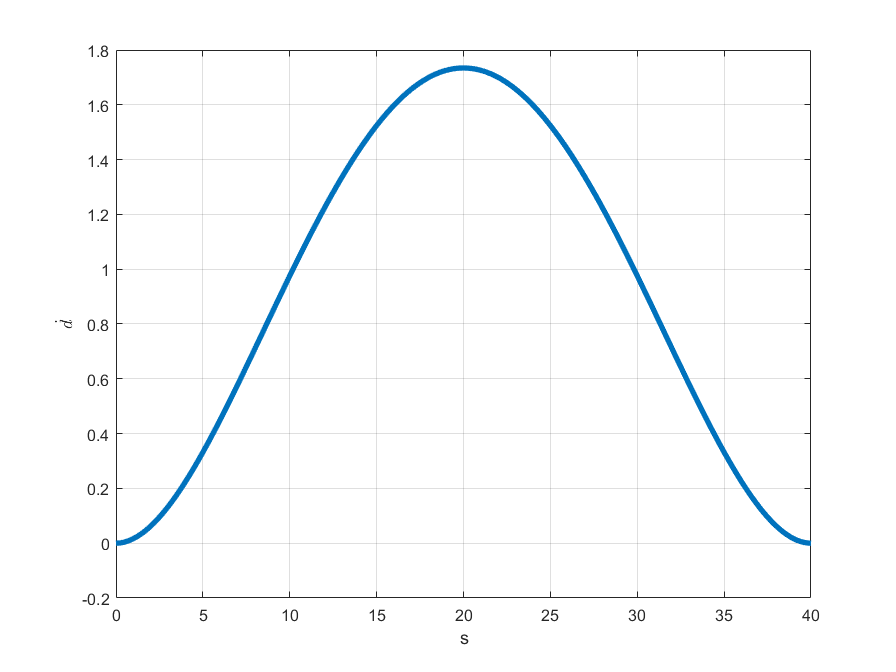

traj_ddot = a(2)+2*a(3)*tP+3*a(4)*tP.^2+4*a(5)*tP.^3+5*a(6)*tP.^4;
plot(traj_s,traj_ddot,"LineWidth",4);
xlabel("s")
ylabel('$\dot{d}$','interpreter','latex')
grid on

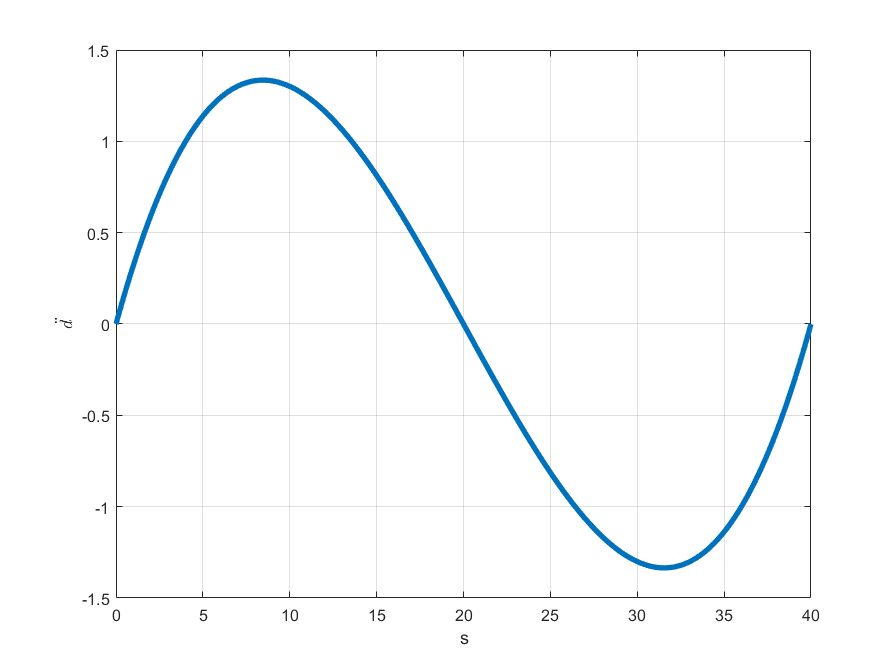

traj_ddotdot = 2*a(3)+6*a(4)*tP+12*a(5)*tP.^2+20*a(6)*tP.^3;
plot(traj_s,traj_ddotdot,"LineWidth",4);
xlabel("s")
ylabel('$\ddot{d}$','interpreter','latex')
grid on

The function generateMinJerkTrajectory considers the initial time as zero relative to the final time of the trajectory. The final time of the trajectory defines, in how many seconds do we want the vehicle to finish the lane-changing maneuver. If this value is very small, then it might result with a very sharp turn and also possible impossible to realize according to the constraints of the vehicle model. Also note that the longitudinal speed of the vehicle plays an important role for realizing the lateral displacement as the vehicle cannot strafe left or right, the longitudinal speed being zero also means that the lateral speed is zero. The trajectory is then sampled for the continuous lateral controller to get the reference waypoints (Pure Pursuit) or the reference poses of the sampled points (Lateral Stanley Controller) on the trajectory. To get the pose, the additional variable $\theta_r$ the reference orientation angle can be obtained by using the `atan2` function on the lateral speed  at the next points over the longitudinal speed.


$$\theta_r \left(t\right)=\frac{\dot{d} \left(t\right)}{\dot{s} \left(t\right)}$$


The code snipped below is creating all the reference points of the trajectory at the time when the trajectory is generated and storing them for the Pure Pursuit controller.

### Using Pure Pursuit

Trajectory output used as separate waypoints and the Pure Pursuit tracking algorithm derives the steering angle for the kinematic bicycle model of the vehicle to track these points.

### Using Lateral Stanley Controller

Trajectory output used as separate waypoints and the Lateral Stanley Controller algorithm gets the pose of the reference waypoints to derive the steering angle for the kinematic bicycle model of the vehicle to track these points.

### Overtaking Maneuver

After passing Vehicle 1 and having enough safe distance to not cut directly in front of Vehicle 1, Vehicle 2 derives another minimum jerk trajectory back to the original lane. This process is very similar to the left lane-change, only changing the initial and final boundary conditions of the trajectory to be generated, it derives the optimal trajectory waypoints. These same waypoints are also used by either the Pure Pursuit or the Lateral Stanley Controller for the vehicle kinematic bicycle model to track the desired trajectory correctly.

The Pure Pursuit and the Lateral Stanley Controller work in Cartesian Coordinates at the moment as they get the Cartesian Coordinates of the vehicles at all times. Therefore an algorithm that transforms the optimal trajectory defined the Frenet Frame back to the Cartesian Coordinates is needed. In the next section, the transformation from <s,d> back to <x,y> along with an extra variable $\theta$ for orientation for Lateral Stanley Controller is explained.

## Frenet to Cartesian Coordinate Transformation

### Straight Road - Frenet to Cartesian

After the vehicle localizes itself according to the Frenet Frame, it will plan its next intermediate waypoint to visit. If the vehicle is going on the right lane, doesn't matter if it is a straight road or a curved road, it will be traveling along the $s\;\textrm{axis}\;$with a lateral displacement of $d=0$. So the next point should be $\acute{s} =s+\Delta s$ with also $d=0$. As the lateral controllers give commands in the Cartesian Coordinate System (this might be updated in the future to work also according to vehicle's frame) they need either the coordinates of the next waypoints for Pure Pursuit Lateral Controller or the reference pose for the Stanley Lateral Controller. The required outputs are calculated similarly by first calculating the route vector, its magnitude along the $s$ axis and by adding the starting point of the route as everything is relative to the route but we need the global coordinates. Here there is also an extra output required by the Stanley Controller which is the reference orientation of the point. As this point lies on the route which is a straight line, it can easily be calculated by the atan2d function in degrees, as the Lateral Stanley Controller Block in MATLAB requires this input in degrees.

### Curved Road - Frenet to Cartesian

The vector operations and manipulations are done in a reverse order according to the global coordinates of the reference road segment. Again this is done more efficiently with a separate frame for straight roads and curved roads.

## Check if Waypoint Reached

At every loop, according to the distance left to the intermediate waypoint on the path or the destination, a check must happen to restart the "s" value and update the road segment. As the motion related to the road segment happens in the local trajectory planner, the operations explained above should also be followed with a function that checks if the waypoint (the end point of the road segment) is reached. This check happens inside the vehicle class.

The check for the waypoint reached happens either according to the "s" value or the Euclidian norm to the end point of the segment. The reason why there are two checks in conjuction is that, if a vehicle is changing lanes, it might finish the current route but not necessarily pass from the destination point which is by default located on the right lane. When the distance to the end point is smaller than the threshold value (1 meter in the code above), the next road segment information is loaded as the currentTrajectory. This is necessary to keep the continuity and to ensure the smoothness of the vehicle's motion. The flag for replaning the global plan is also set to `true` to check if there is a need for replanning by the pathfinder algorithm in case there is the preassumed traffic conditions have changed.

# IV- Longitudinal and Lateral Controllers

## Longitudinal Controllers according to the Driving Mode Switch

As previously mentioned in [Documentation.mlx](matlab:open('./Documentation.mlx')) the driving modes are defined as:

- Free drive mode (go with the maximum allowed speed: Speed Reference)

- Follow the leading vehicle (the reference speed is generated using the Platoon controller block)

- Emergency Brake (reference speed is zero and minimum deceleration is applied directly to the vehicle)

- Slow down and stop until the intersection is clear (the speed reference is controlled by the distance to the conflict area in the intersection: slow down until 10 meters then 0 reference speed to stop smoothly)

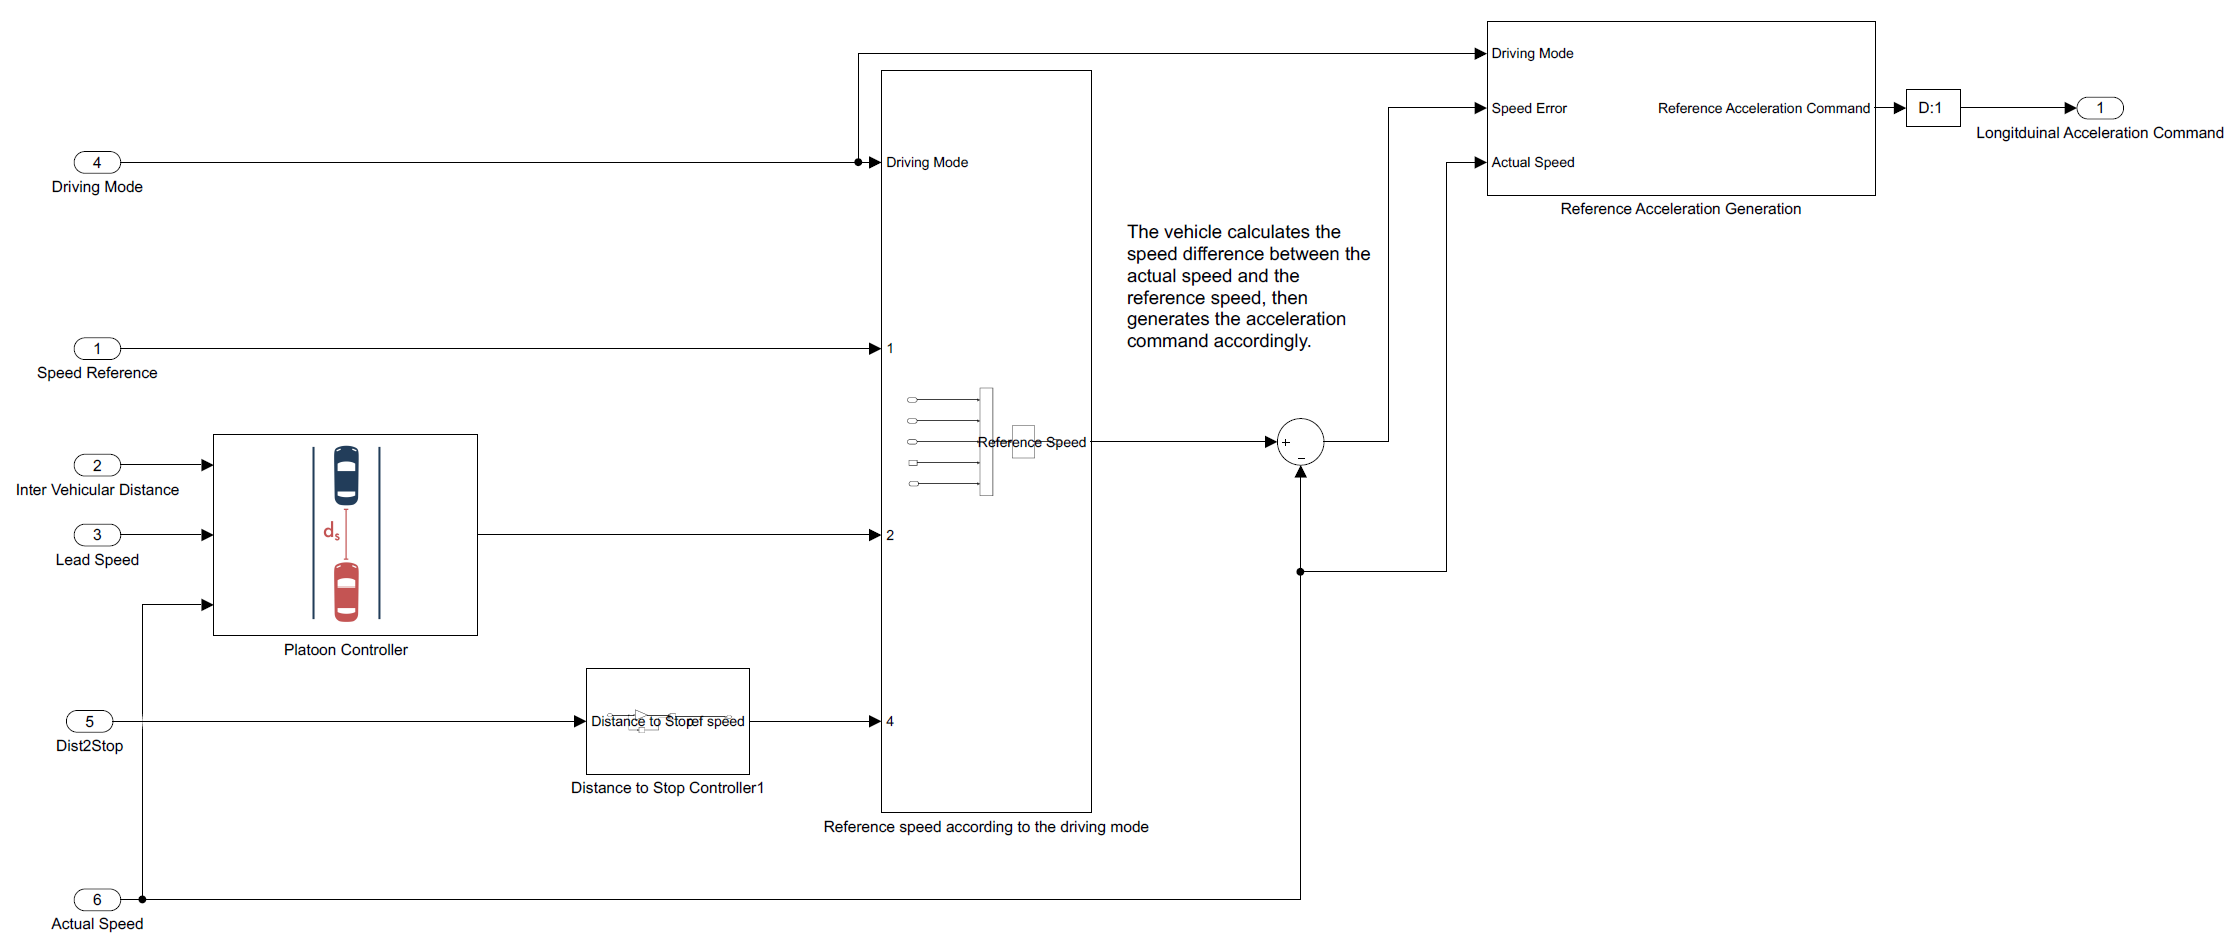

### 1- Free drive mode

The vehicle accelerates to reach the `maxSpeed` defined in the Vehicle properties according to the driving scenario defined in *load_scenario.m*. Therefore the reference speed is equal to the vehicle's maximum allowed speed.


$$v_{\mathrm{ref}} =v_{\mathrm{max}}$$


After the speed reference is generated and passes through the switch, the difference with the actual speed is taken to generate a speed error signal.


$$v_{\mathrm{err}} =v_{\mathrm{ref}} -v_{\mathrm{actual}}$$


This signal goes to the reference acceleration generation block since the vehicle doesn't control the speed directly but controls the reference acceleration. Reference acceleration generation block contains a gear logic which limits the maximum acceleration at a sample time according to the current speed of the vehicle. In lower speeds, the gear is low and the torque that can be generated is higher, so a higher maximum acceleration value is possible. When the speed is higher, the maximum acceleration values decreases. This value is then used for the external output of the saturation block which generates the reference acceleration signal for all the driving modes except for the emergency brake.

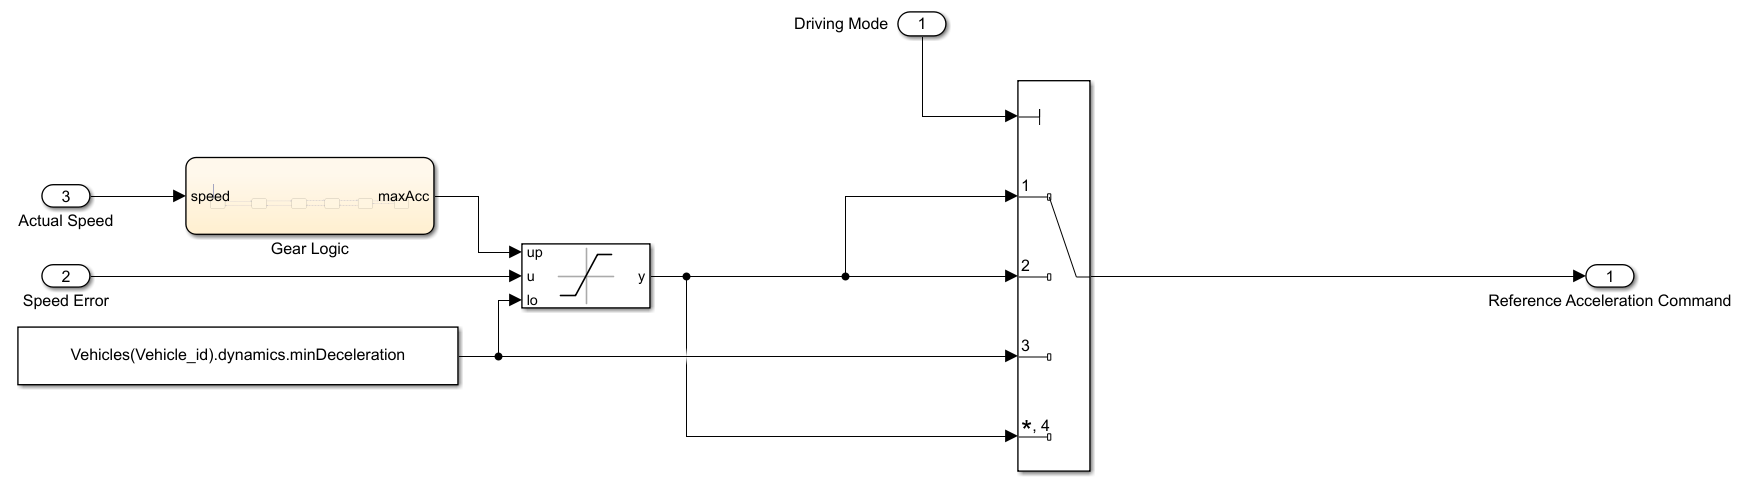

The maximum acceleration is defined according to the current speed of the vehicle in the *Gear Logic* stateflow model as follows:

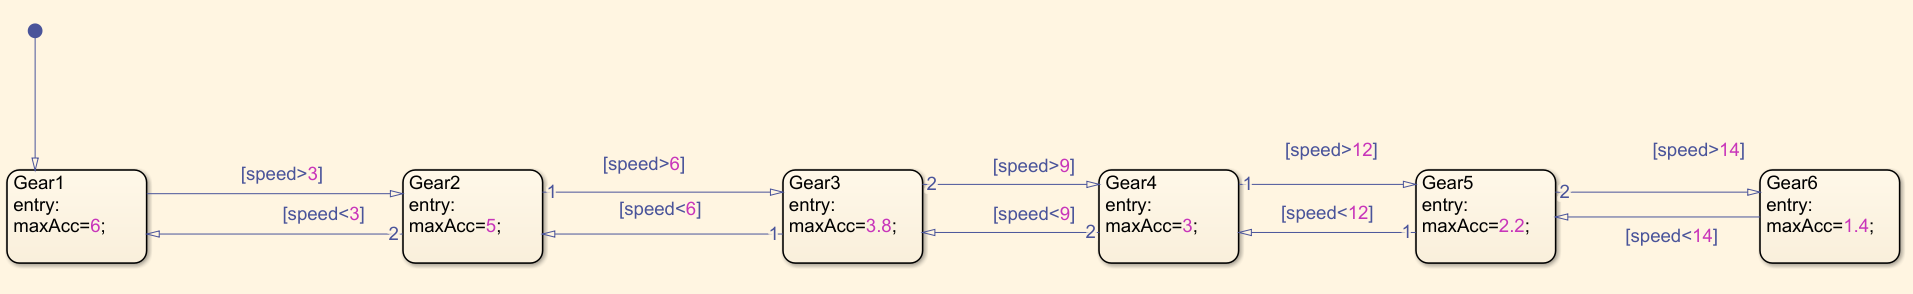

### 2- Platooning Mode (Vehicle Following Mode)

There are alternatives to the Platooning Mode subsystem but the main one used in most vehicles is the PID-based Platooning Controller. This variant is computationally a much cheaper alternative to the MPC-based Platooning Controller. The formula for following a slower vehicle is as follows:


$$d_{\mathrm{ref}} =\tau_h v\left(t\right)+d_s$$
 

where $d_{\mathrm{ref}}$ is the reference intervehicular distance, $\tau_h$ is the headway time between vehicles which is 1.4 seconds by default,  $v\left(t\right)$is the current speed of the following vehicle (the one which tries to follow the leading vehicle with a safe distance), and $d_s$ is the default safe distance which can also be thought as the desired distance when both vehicles come to a standstill where their speeds are zero.

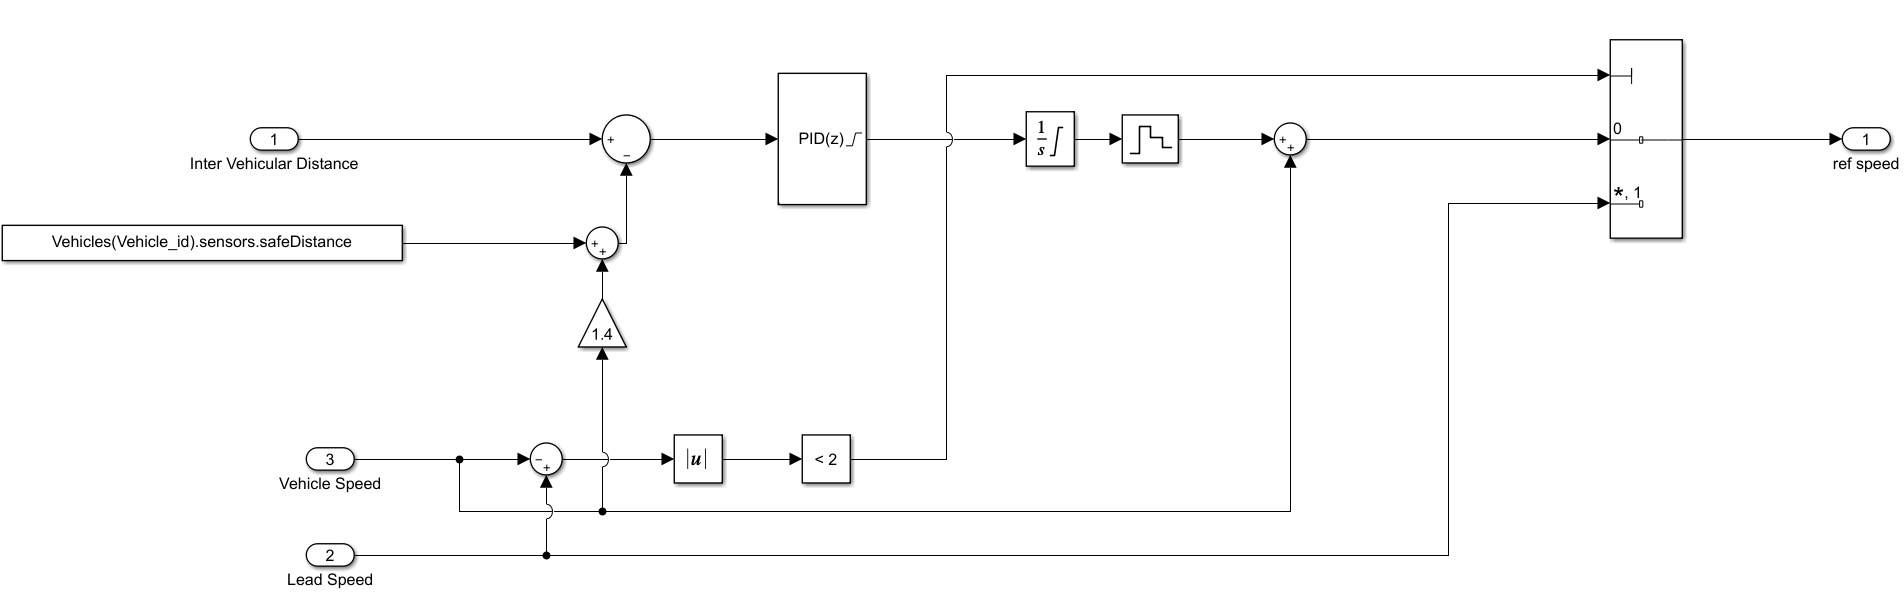

To ensure convergence when the absolute value of the speed difference falls below the threshold value (equal to 2 meters per second in the figure above), the switch sets the following vehicle's reference speed equal to the leading vehicle's speed. This enables a smooth following without overshoots or oscilatory behaviors. The PID controller generates the reference acceleration value that is required to follow the leading vehicle safely and then it is followed by an integrator to determine the reference speed from the acceleration value which also adds up the current speed as the integrator constant.

### 3- Emergency Brake

For emergency brake, the driving mode signal (==3) the vehicle's minimum deceleration value is applied as a constant value (defined as *-g* value by default).

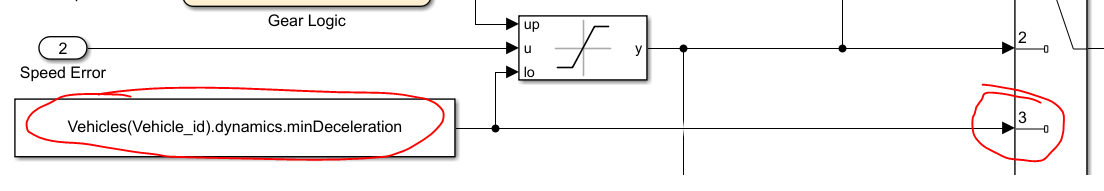

### 4- Stop before Intersection Mode

When the `drivingMode==4` then the distance to the next waypoint which is the waypoint before the intersection where vehicle has to stop and wait for the clearance of the intersection is taken as the input for a P controller with a low gain value to reduce its reference speed slowly. This enables a smooth slowing down before the intersection rather than a sharp brake. When the distance falls below 10 meters, the reference speed is then equal to zero to ensure that the vehicle doesn't overshoot and stops without entering the conflict zone of the intersection.

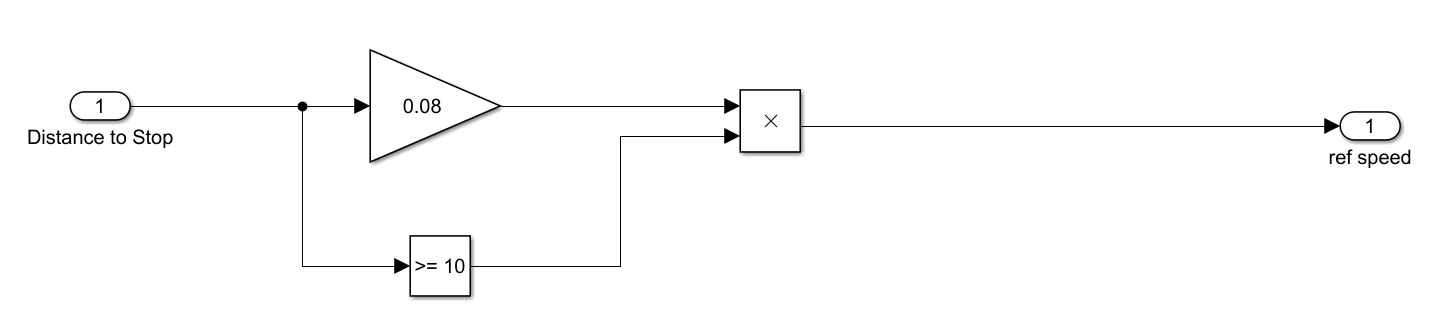

### Longitudinal Reachability Analysis

For the leading vehicle a [longitudinal reachability analysis](matlab:open('./Vehicle Functions\LongitudinalReachability.m')) is done to estimate its future position $s$ and velocity $v$ when applying the maximum or minimum possible longitudinal acceleration $a_{max}$ or $a_{min}$ for a specified time horizon. The future states at time step $k+1$ can be calculated by the following expression with $T_{s}$ being the sample time:


$$$\left[ \begin{array}{r}
s(k+1) \\ 
v(k+1)\\
\end{array}\right]$

=

$\left[ \begin{array}{rr}
1 & (k+1)T_{s}  \\ 
0 & 1  \\
\end{array}\right]$

$\left[ \begin{array}{r}
s(0) \\ 
v(0) \\ 
\end{array}\right]$

+

$\left[ \begin{array}{r}
\frac{T_{s}^2}{2}  \sum\nolimits_{j=0}^k\ (2k + 1 - 2j)a_{j} \\
T_{s} \sum\nolimits_{j=0}^k\ a_{j} \\
\end{array}\right]$$$


With the maximum or minimum acceleration being constant, this simplifies to:


$$$\left[ \begin{array}{r}
s(k+1) \\ 
v(k+1)\\
\end{array}\right]$

=

$\left[ \begin{array}{rr}
1 & (k+1)T_{s}  \\ 
0 & 1  \\
\end{array}\right]$

$\left[ \begin{array}{r}
s(0) \\ 
v(0) \\ 
\end{array}\right]$

+

$\left[ \begin{array}{r}
\frac{T_{s}^2}{2} \ a \sum\nolimits_{j=0}^k\ (2j + 1) \\
 \ T_{s}  (k + 1)   a   \\
\end{array}\right]$$$


## Lateral Controllers - Variant Subsystem

### a) Lateral Stanley Controller

The Lateral Stanley Controller can also be used for path tracking. Using the kinematic bicycle model, the inputs are:

- The reference pose **[x_ref, y_ref, θ_ref]**: While only considering forward motion, the reference location x_ref, y_ref is the point on the path which is closest to the center of the vehicle's front axle. The reference angle θ_ref is the orientation at this reference location on the path in degrees.

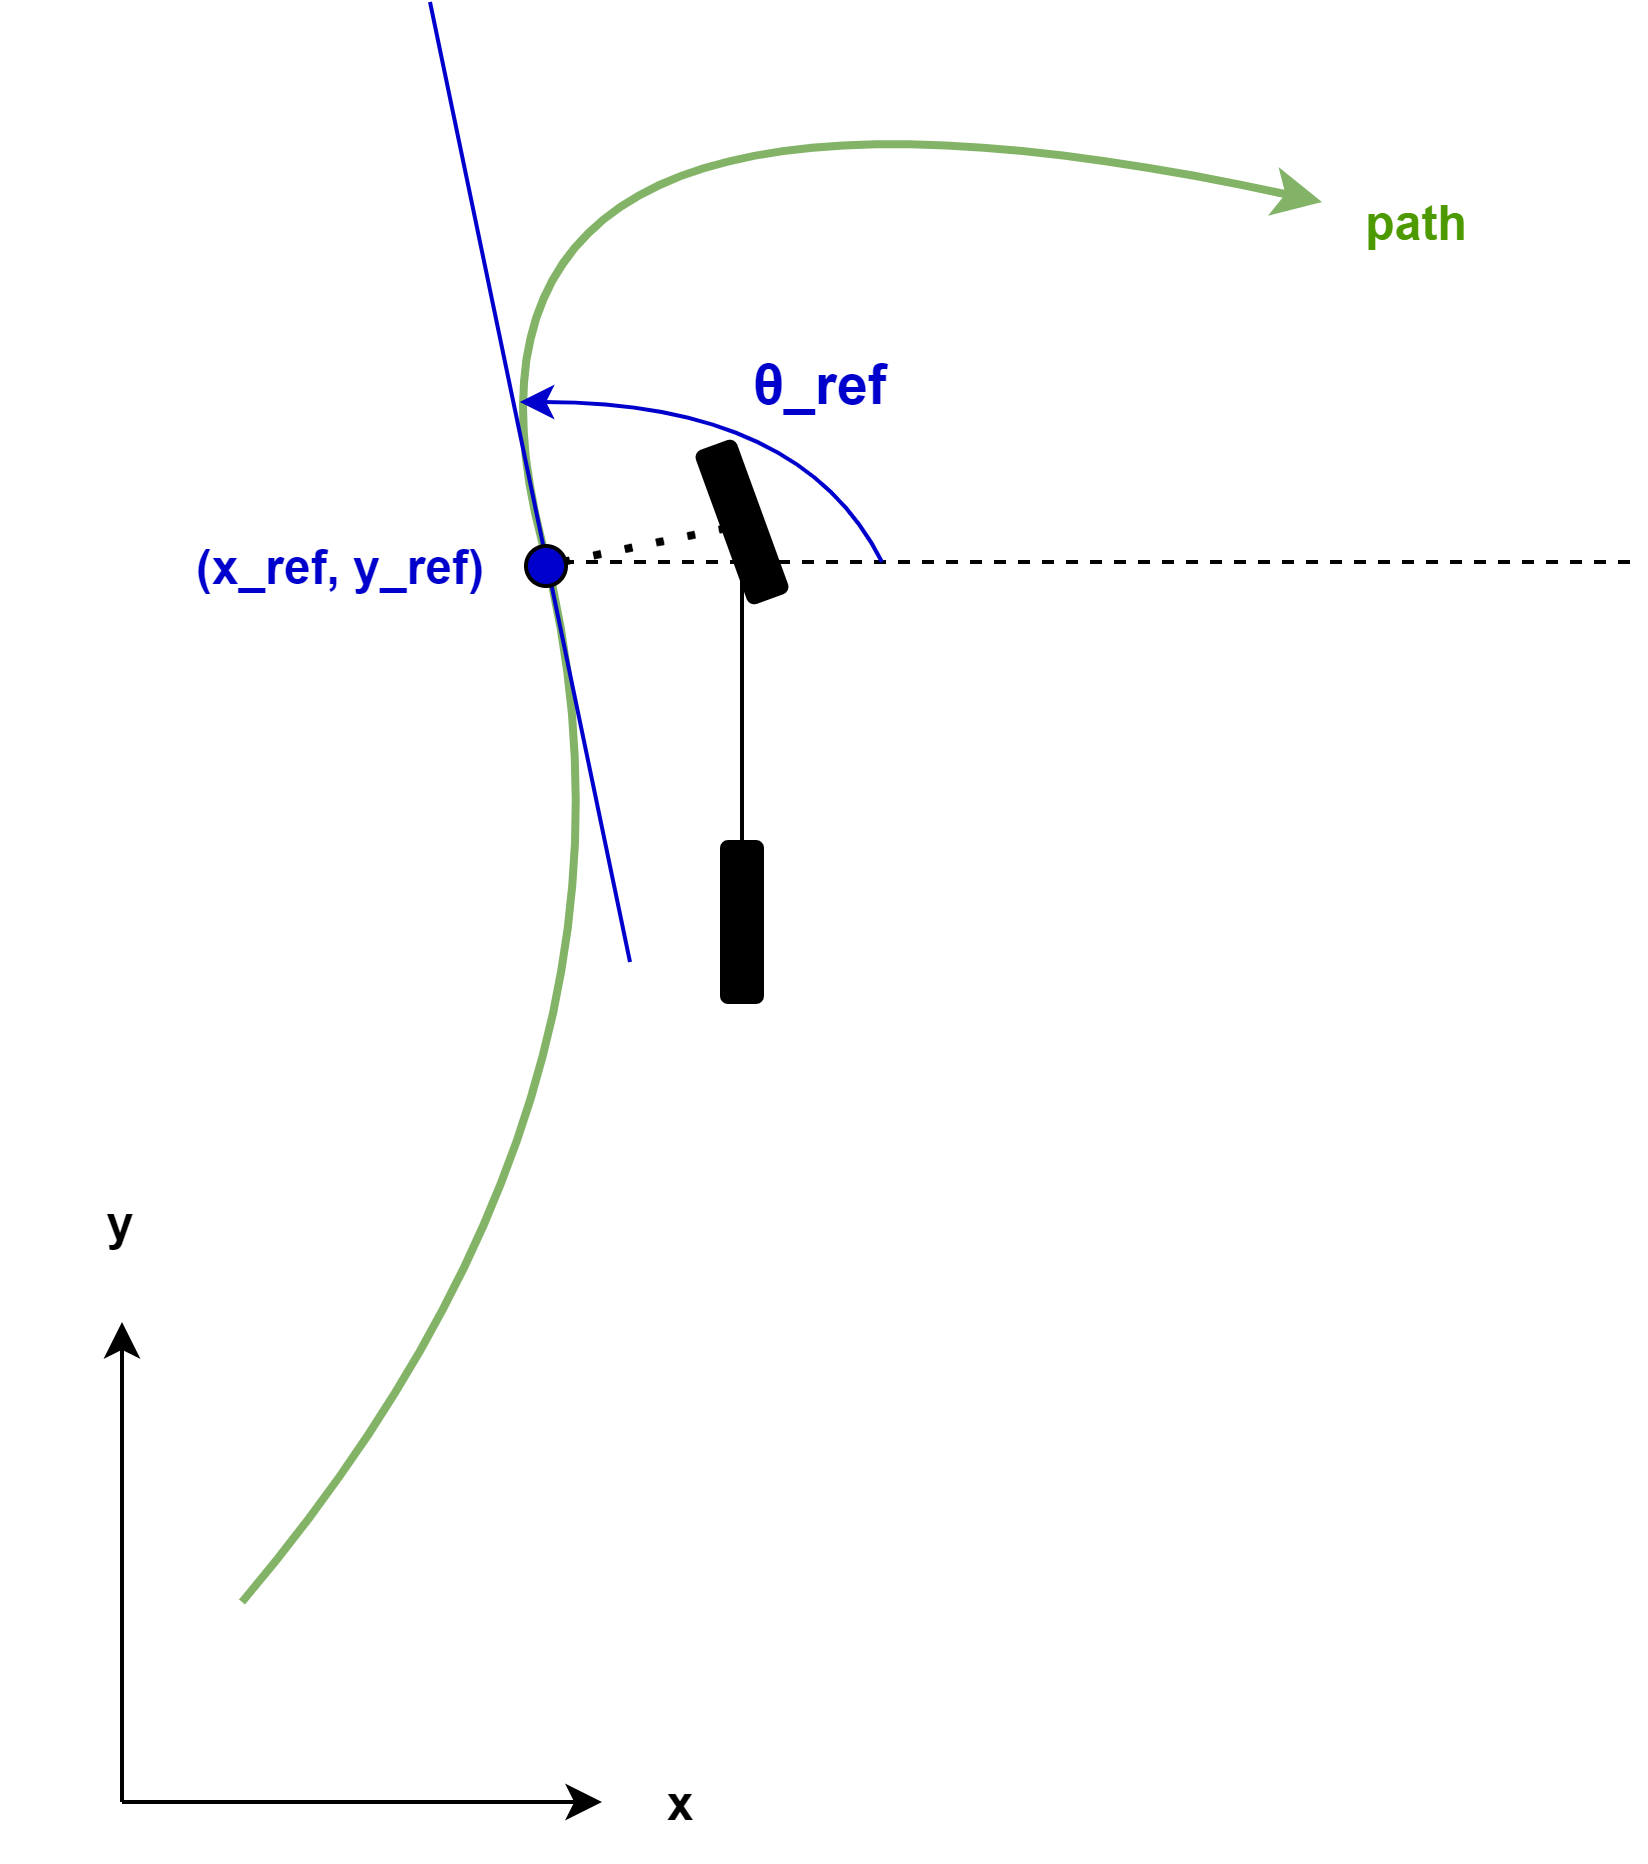

- The current pose **[x, y, θ]**: This is the current pose of the vehicle according to the center of the vehicle's rear axle. The current orientation θ must be in degrees.

- The current velocity of the vehicle in $\frac{m}{s}$

- The vehicle's direction: The constant 1 is used for forward motion.

The controller outputs the steering angle $\delta$ in degrees. Therefore, to use this angle as the input for the bicycle kinematic model, a transformation to radians is necessary.

**Position Gain Of Forward Motion:** To tune the controller, the position gain can be adjusted. For forward motion, only the position gain for forward motion needs to be considered. The higher this value is, the more the position error will affect steering angle adjustmens.

#### Steering Control Law

The steering control law considers the cross track error $e(t)$, the vehicles speed $v(t)$ and the vehicle's heading $\psi (t)$ with respect to the closest trajectory segment (see figure below). The reference point is the center of the vehicle's front axle. For the kinematic bicycle model, the steering angle $\delta(t)$ is calculated as follows, with $k$ being the gain and $\delta_{max}$ being the maximum steering angle:


$$\delta(t) =
    \begin{cases}
      \psi(t) + arctan(\frac{k\ e(t)}{v(t)}) & \text{if } |\psi(t) + arctan(\frac{k\ e(t)}{v(t)})| < \delta_{max} \\
      \delta_{max} & \text{if }  \psi(t) + arctan(\frac{k\ e(t)}{v(t)}) \geq \delta_{max} \\
      -\delta_{max}  &  \text{if } \psi(t) + arctan(\frac{k\ e(t)}{v(t)}) \leq \delta_{max} \\
    \end{cases} $$


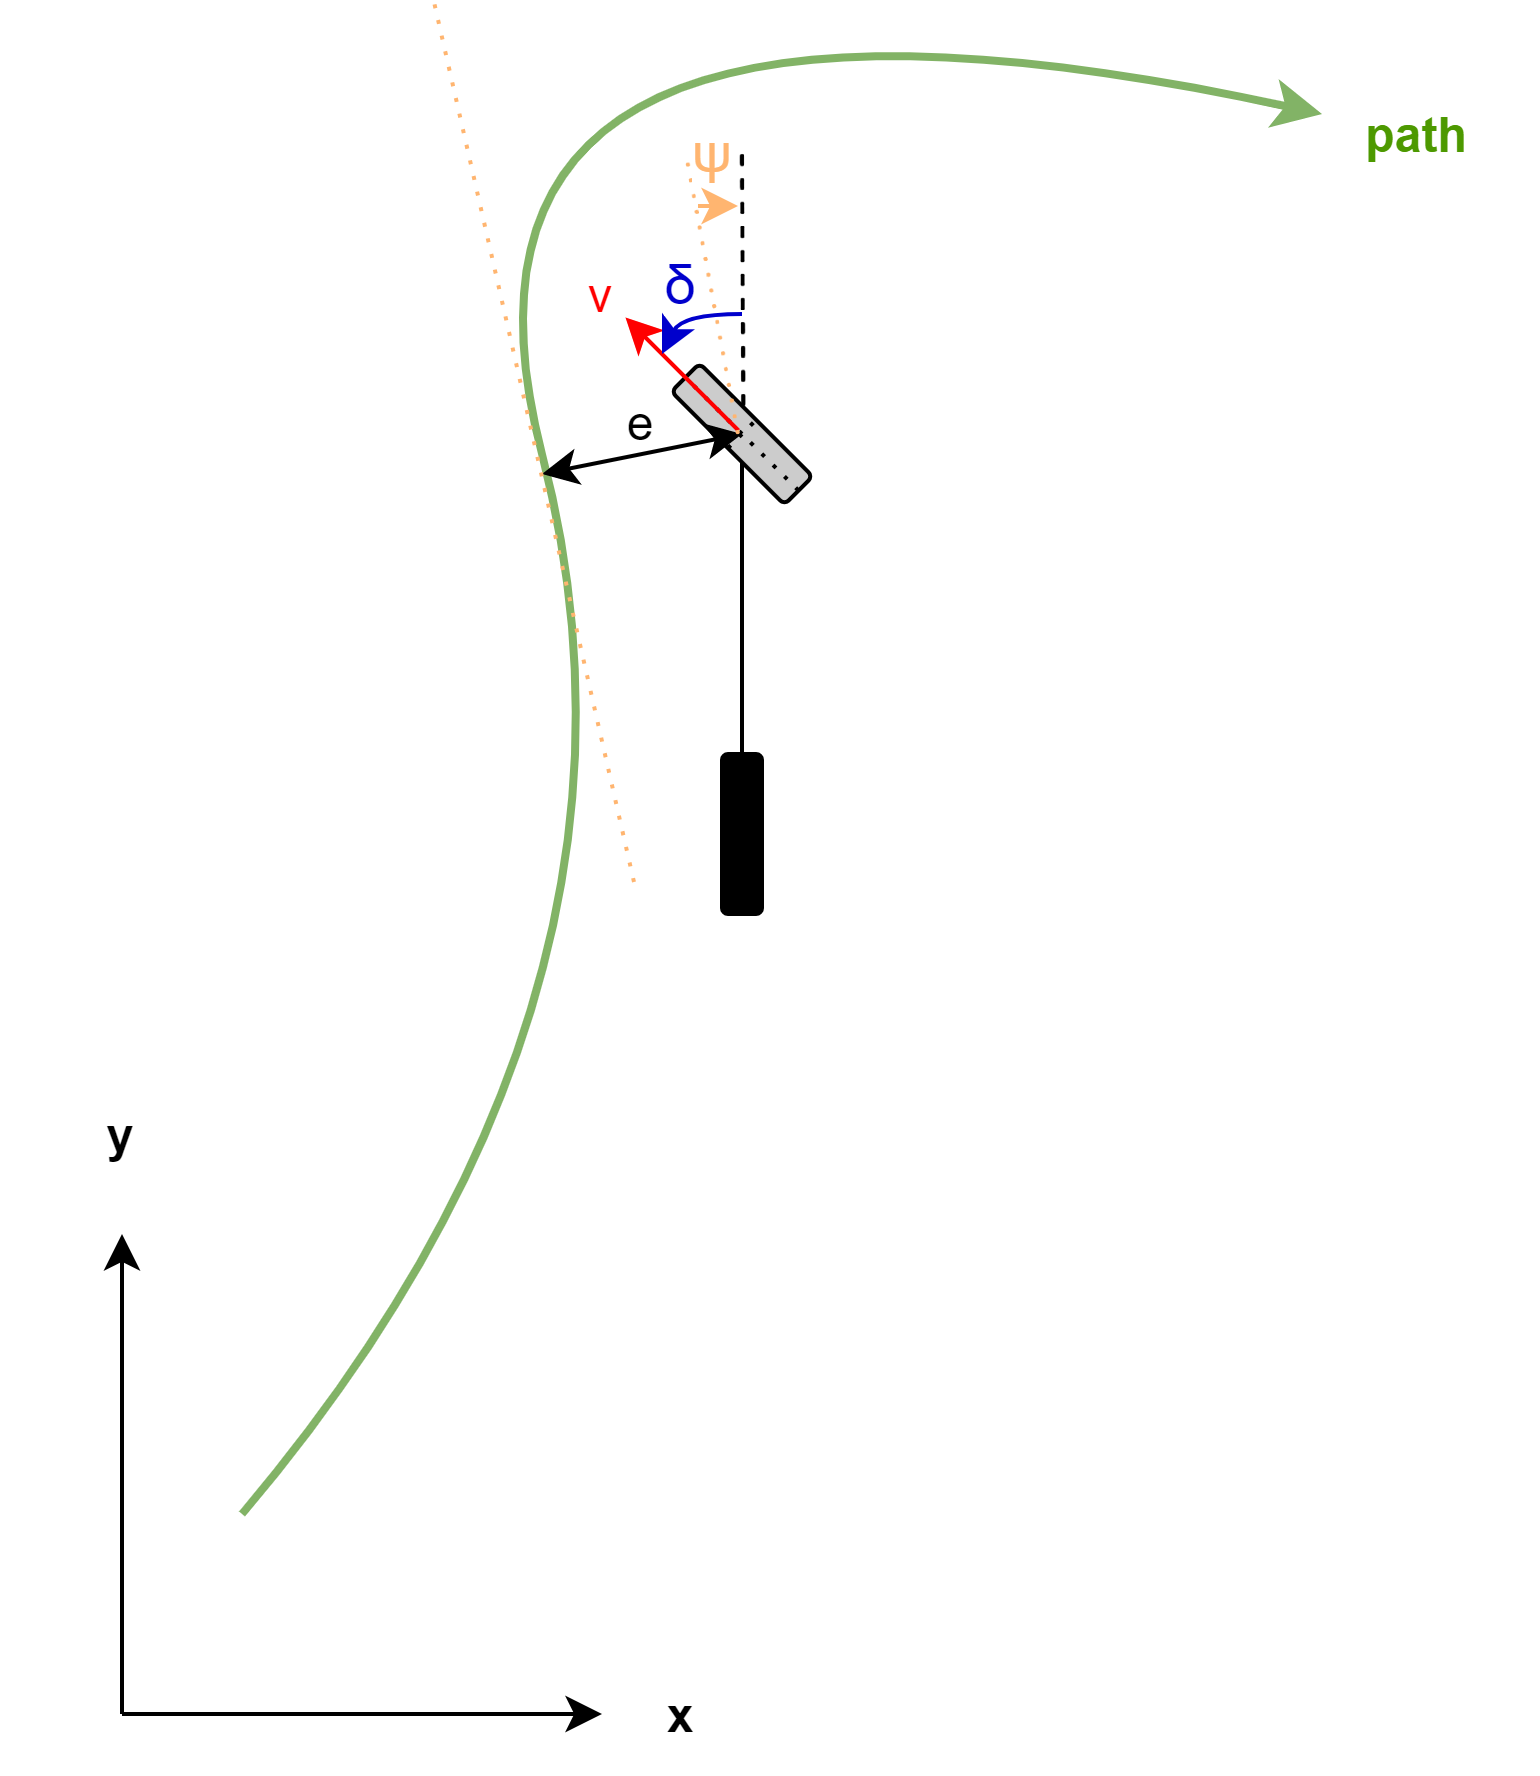

#### References

[https://www.mathworks.com/help/driving/ref/lateralcontrollerstanley.html](https://www.mathworks.com/help/driving/ref/lateralcontrollerstanley.html)

[https://www.youtube.com/watch?v=9Y7kVIJs_JI](https://www.youtube.com/watch?v=9Y7kVIJs_JI)

Hoffmann, Gabriel M., Claire J. Tomlin, Michael Montemerlo, and Sebastian Thrun. "Autonomous Automobile Trajectory Tracking for Off-Road Driving: Controller Design, Experimental Validation and Racing." *American Control Conference*. 2007, pp. 2296–2301. doi:10.1109/ACC.2007.4282788

### b) Pure Pursuit Controller

Pure Pursuit is an algorithm that is used for path tracking. It takes the vehicle's current pose **[x, y, θ] **and the next waypoints' coordinates **[x, y]** as an input. The figure shows the desired path defined by different waypoints (WPs) and the vehicle's current position and orientation. 

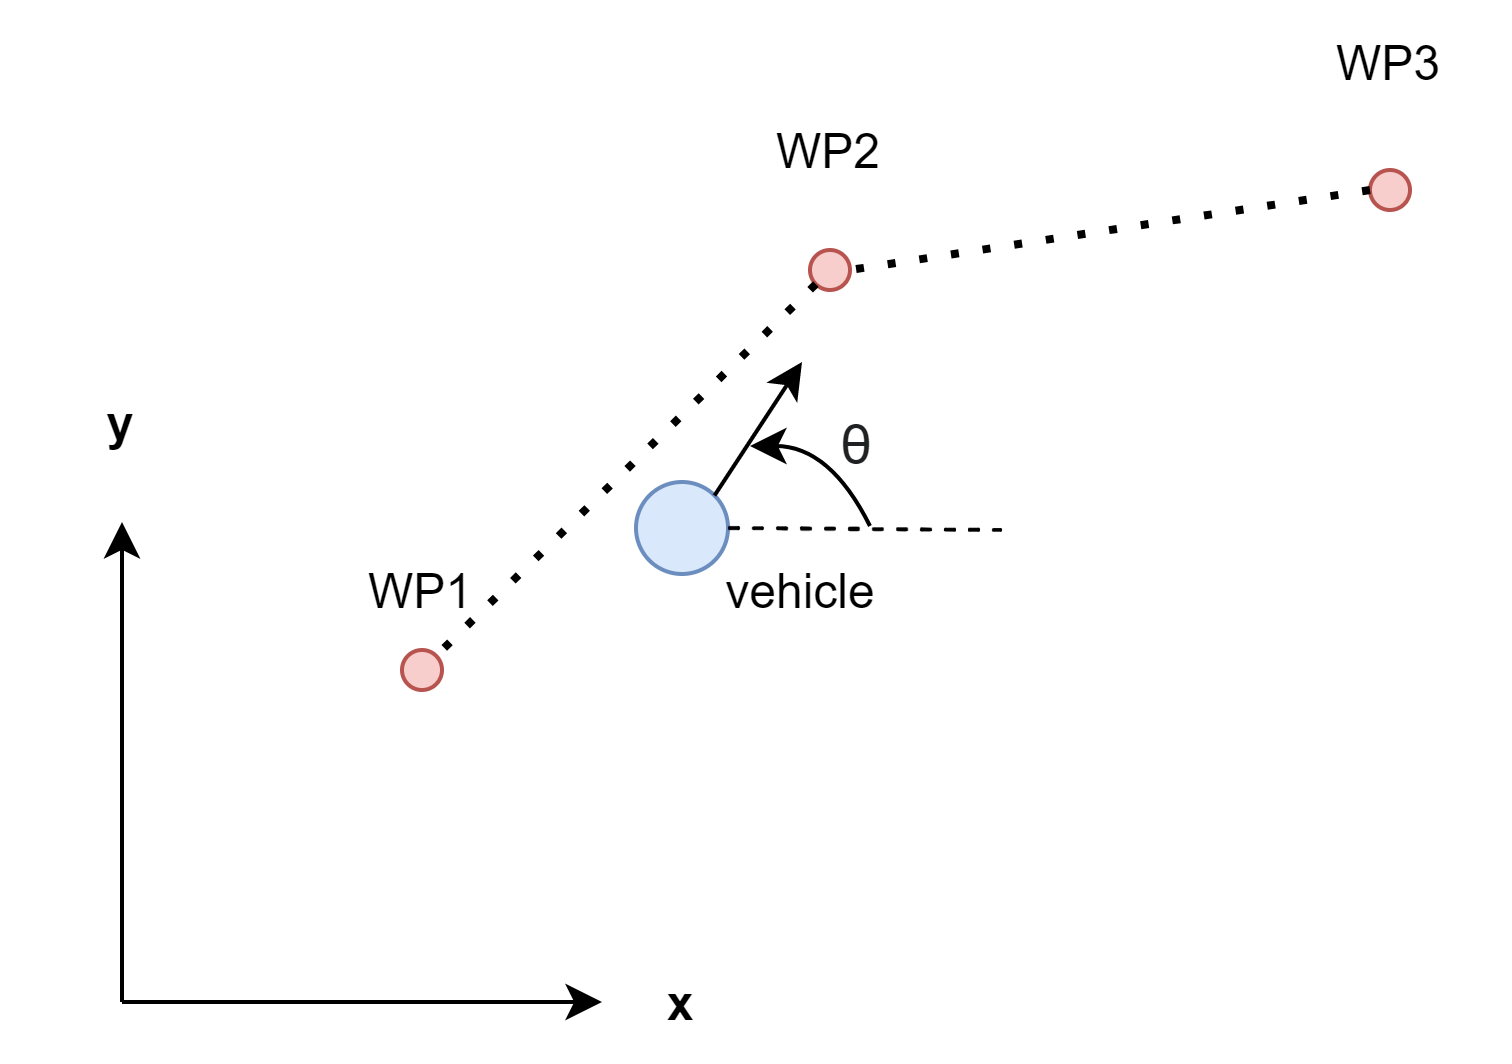

**Look Ahead Distance: **To tune this algorithm, the look ahead distance $l_d$ can be adjusted. It states how far ahead on the path the vehicle should look from its current position. A small look ahead distance results in quickly moving towards the path but thus overshoots are possible. A large look ahead distance on the other hand avoids these overshoots but lets the vehicle move slower towards the path which may result in larger curvatures in corners.

**Steering Angle: **The output that is used to compute the steering angle $\delta$ command for the vehicle kinematic bicycle model, is the target direction $\alpha$:

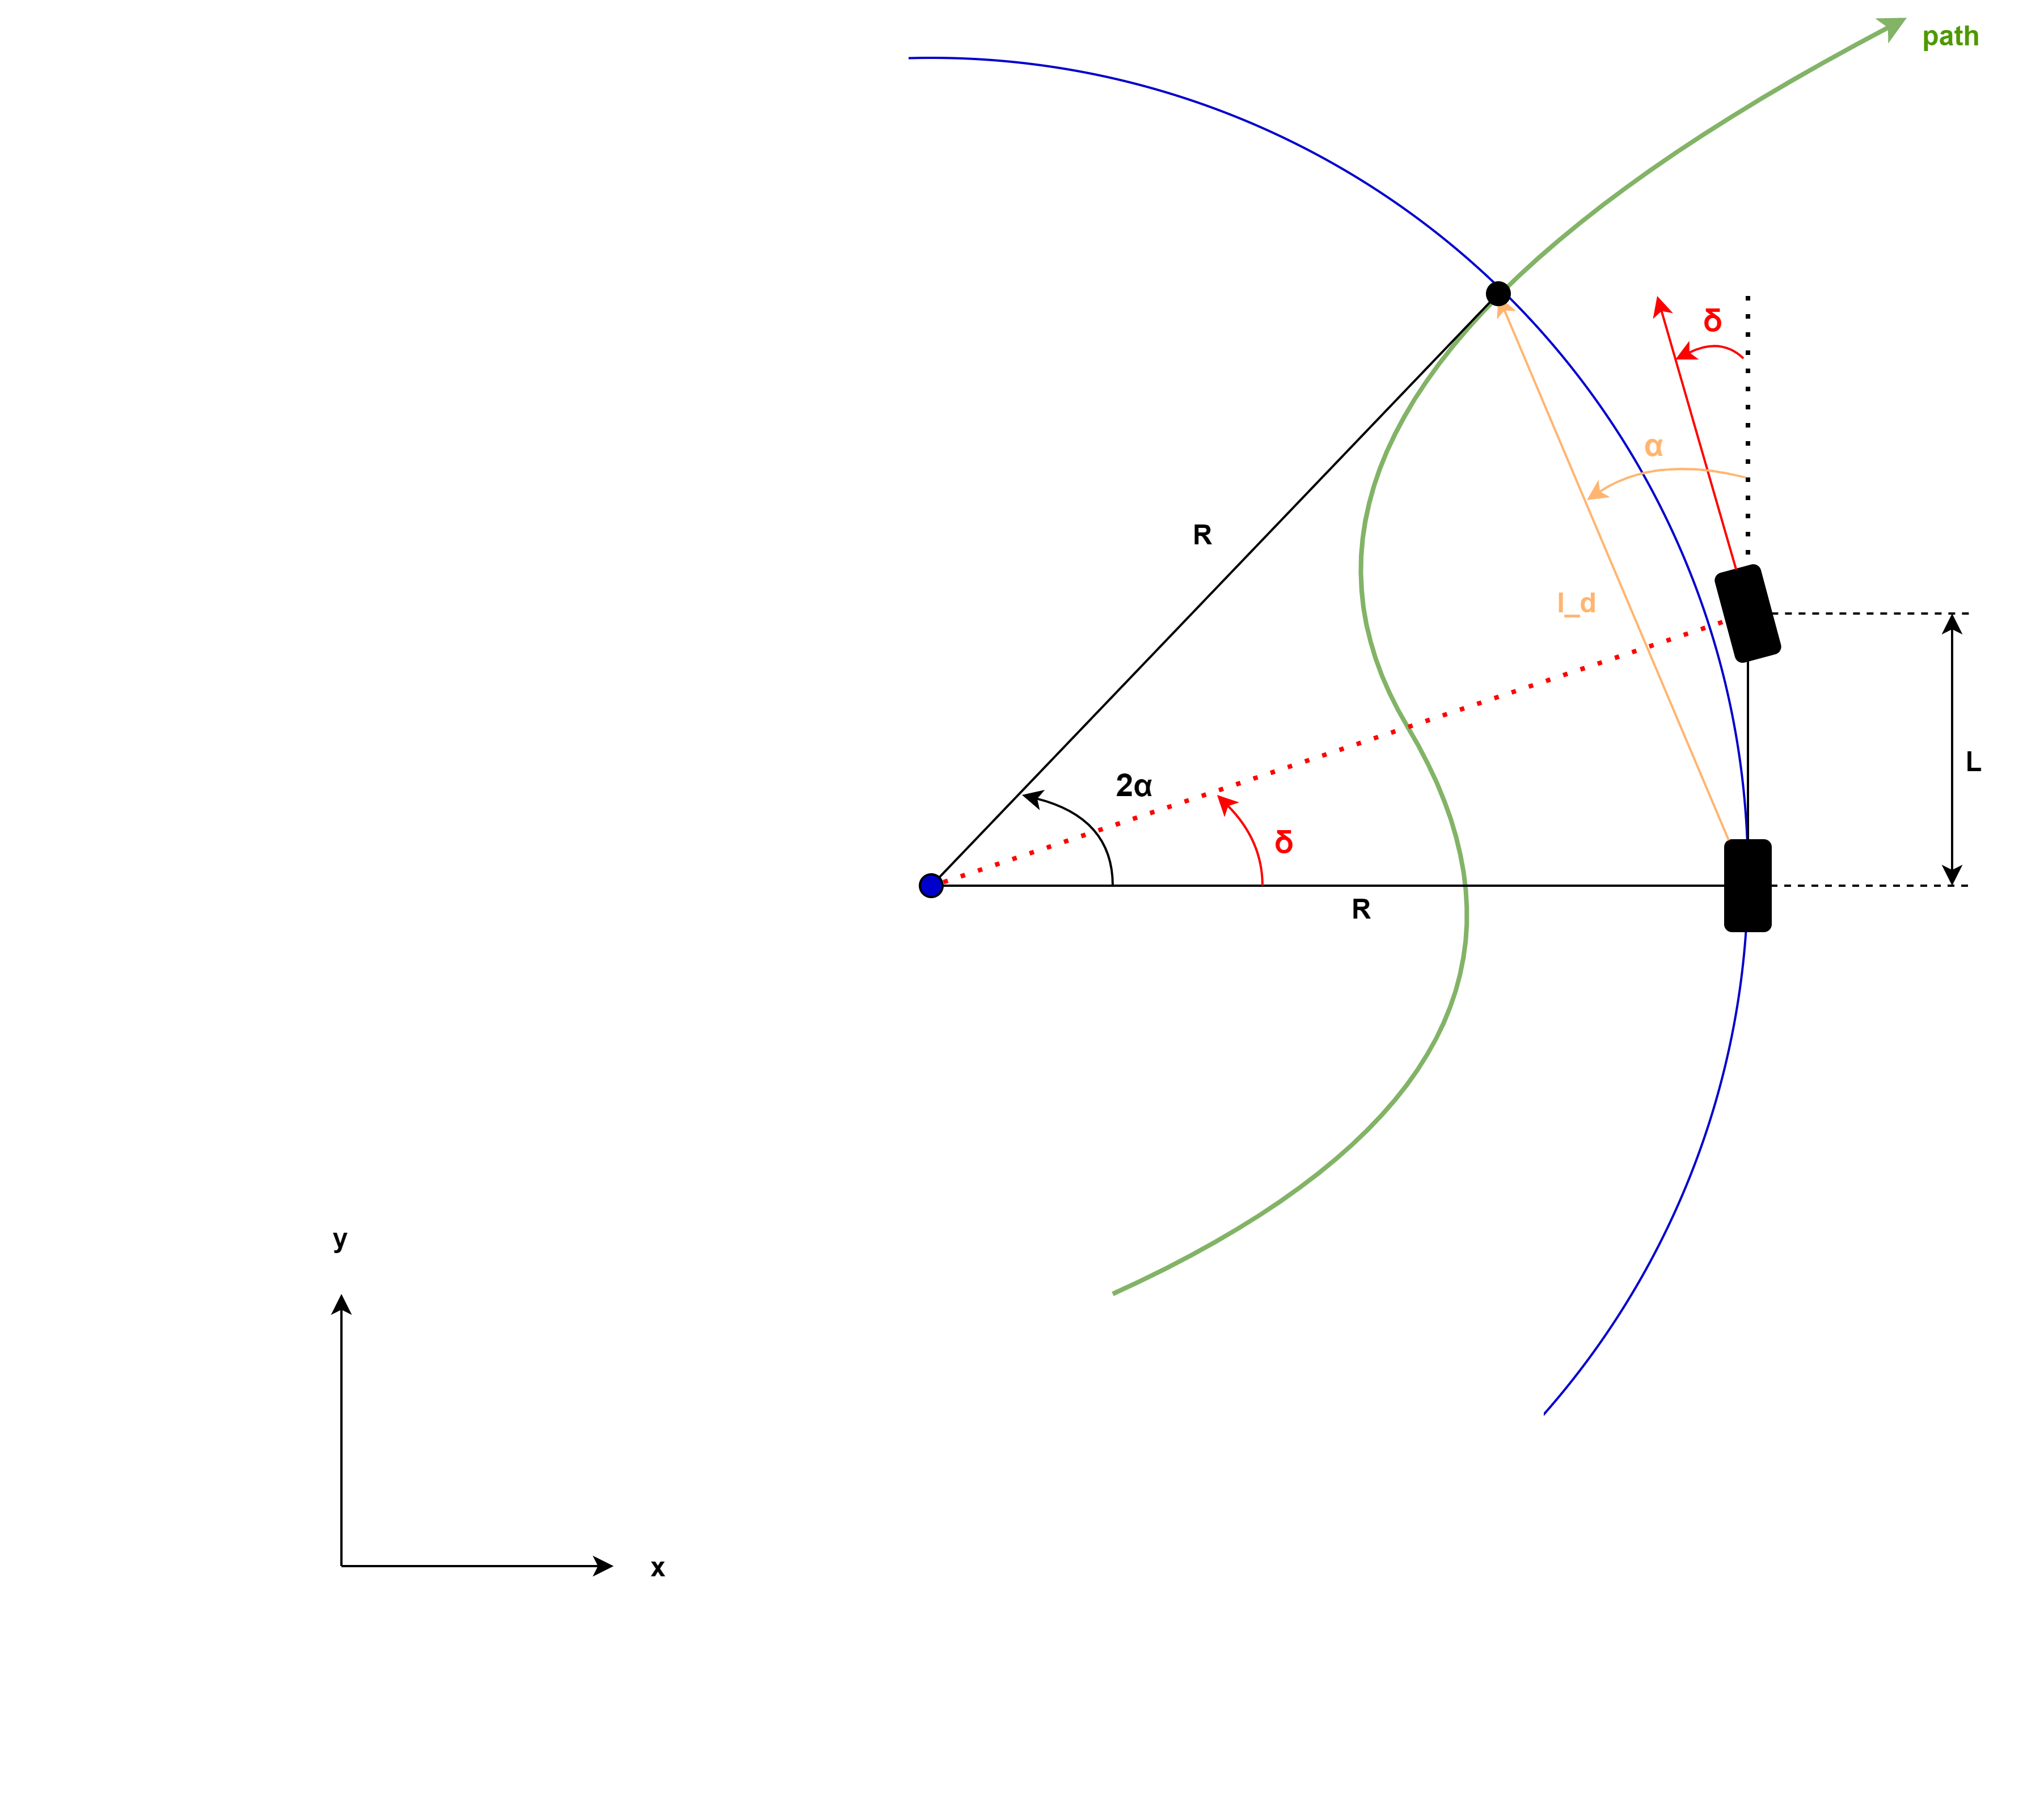

The steering angle $\delta$ can be calculated as follows:


$$\delta = arctan(\frac{L}{R})$$


From the law of sines, $R$ can be obtained:

 
$$\frac{l_d}{sin(2\alpha)} = \frac{R}{sin(\frac{\pi}{2} - \alpha)}$$



$$\frac{l_d}{2\sin(\alpha)\cos(\alpha)} = \frac{R}{cos(\alpha)}$$



$$R = \frac{l_d}{2\sin(\alpha)}$$


This results in:


$$\delta = arctan\left( \frac{2\ L\ sin(\alpha)}{l_{d}} \right)$$


#### References

[https://www.mathworks.com/help/robotics/ug/pure-pursuit-controller.html](https://www.mathworks.com/help/robotics/ug/pure-pursuit-controller.html)

[https://www.youtube.com/watch?v=qYR7mmcwT2w](https://www.youtube.com/watch?v=qYR7mmcwT2w)

Coulter, R. *Implementation of the Pure Pursuit Path Tracking Algorithm*. Carnegie Mellon University, Pittsburgh, Pennsylvania, Jan 1990.

# 5- Vehicle Model

## Kinematic Bicycle Model

The kinematic bicycle model can be used to simulate simplified car-like vehicle dynamics. The coordinate origin of this model is defined at the center of the bicycle's rear axle, which defines the body coordinate system $x_{b}$ and $y_{b}$. For the Simulink block, the used inputs that are the vehicle's velocity $v$ in $\frac{m}{s}$ and the steering angle $\psi$ in rad. The model outputs the state **[x, y, θ] **of the model, which is the vehicle's pose.

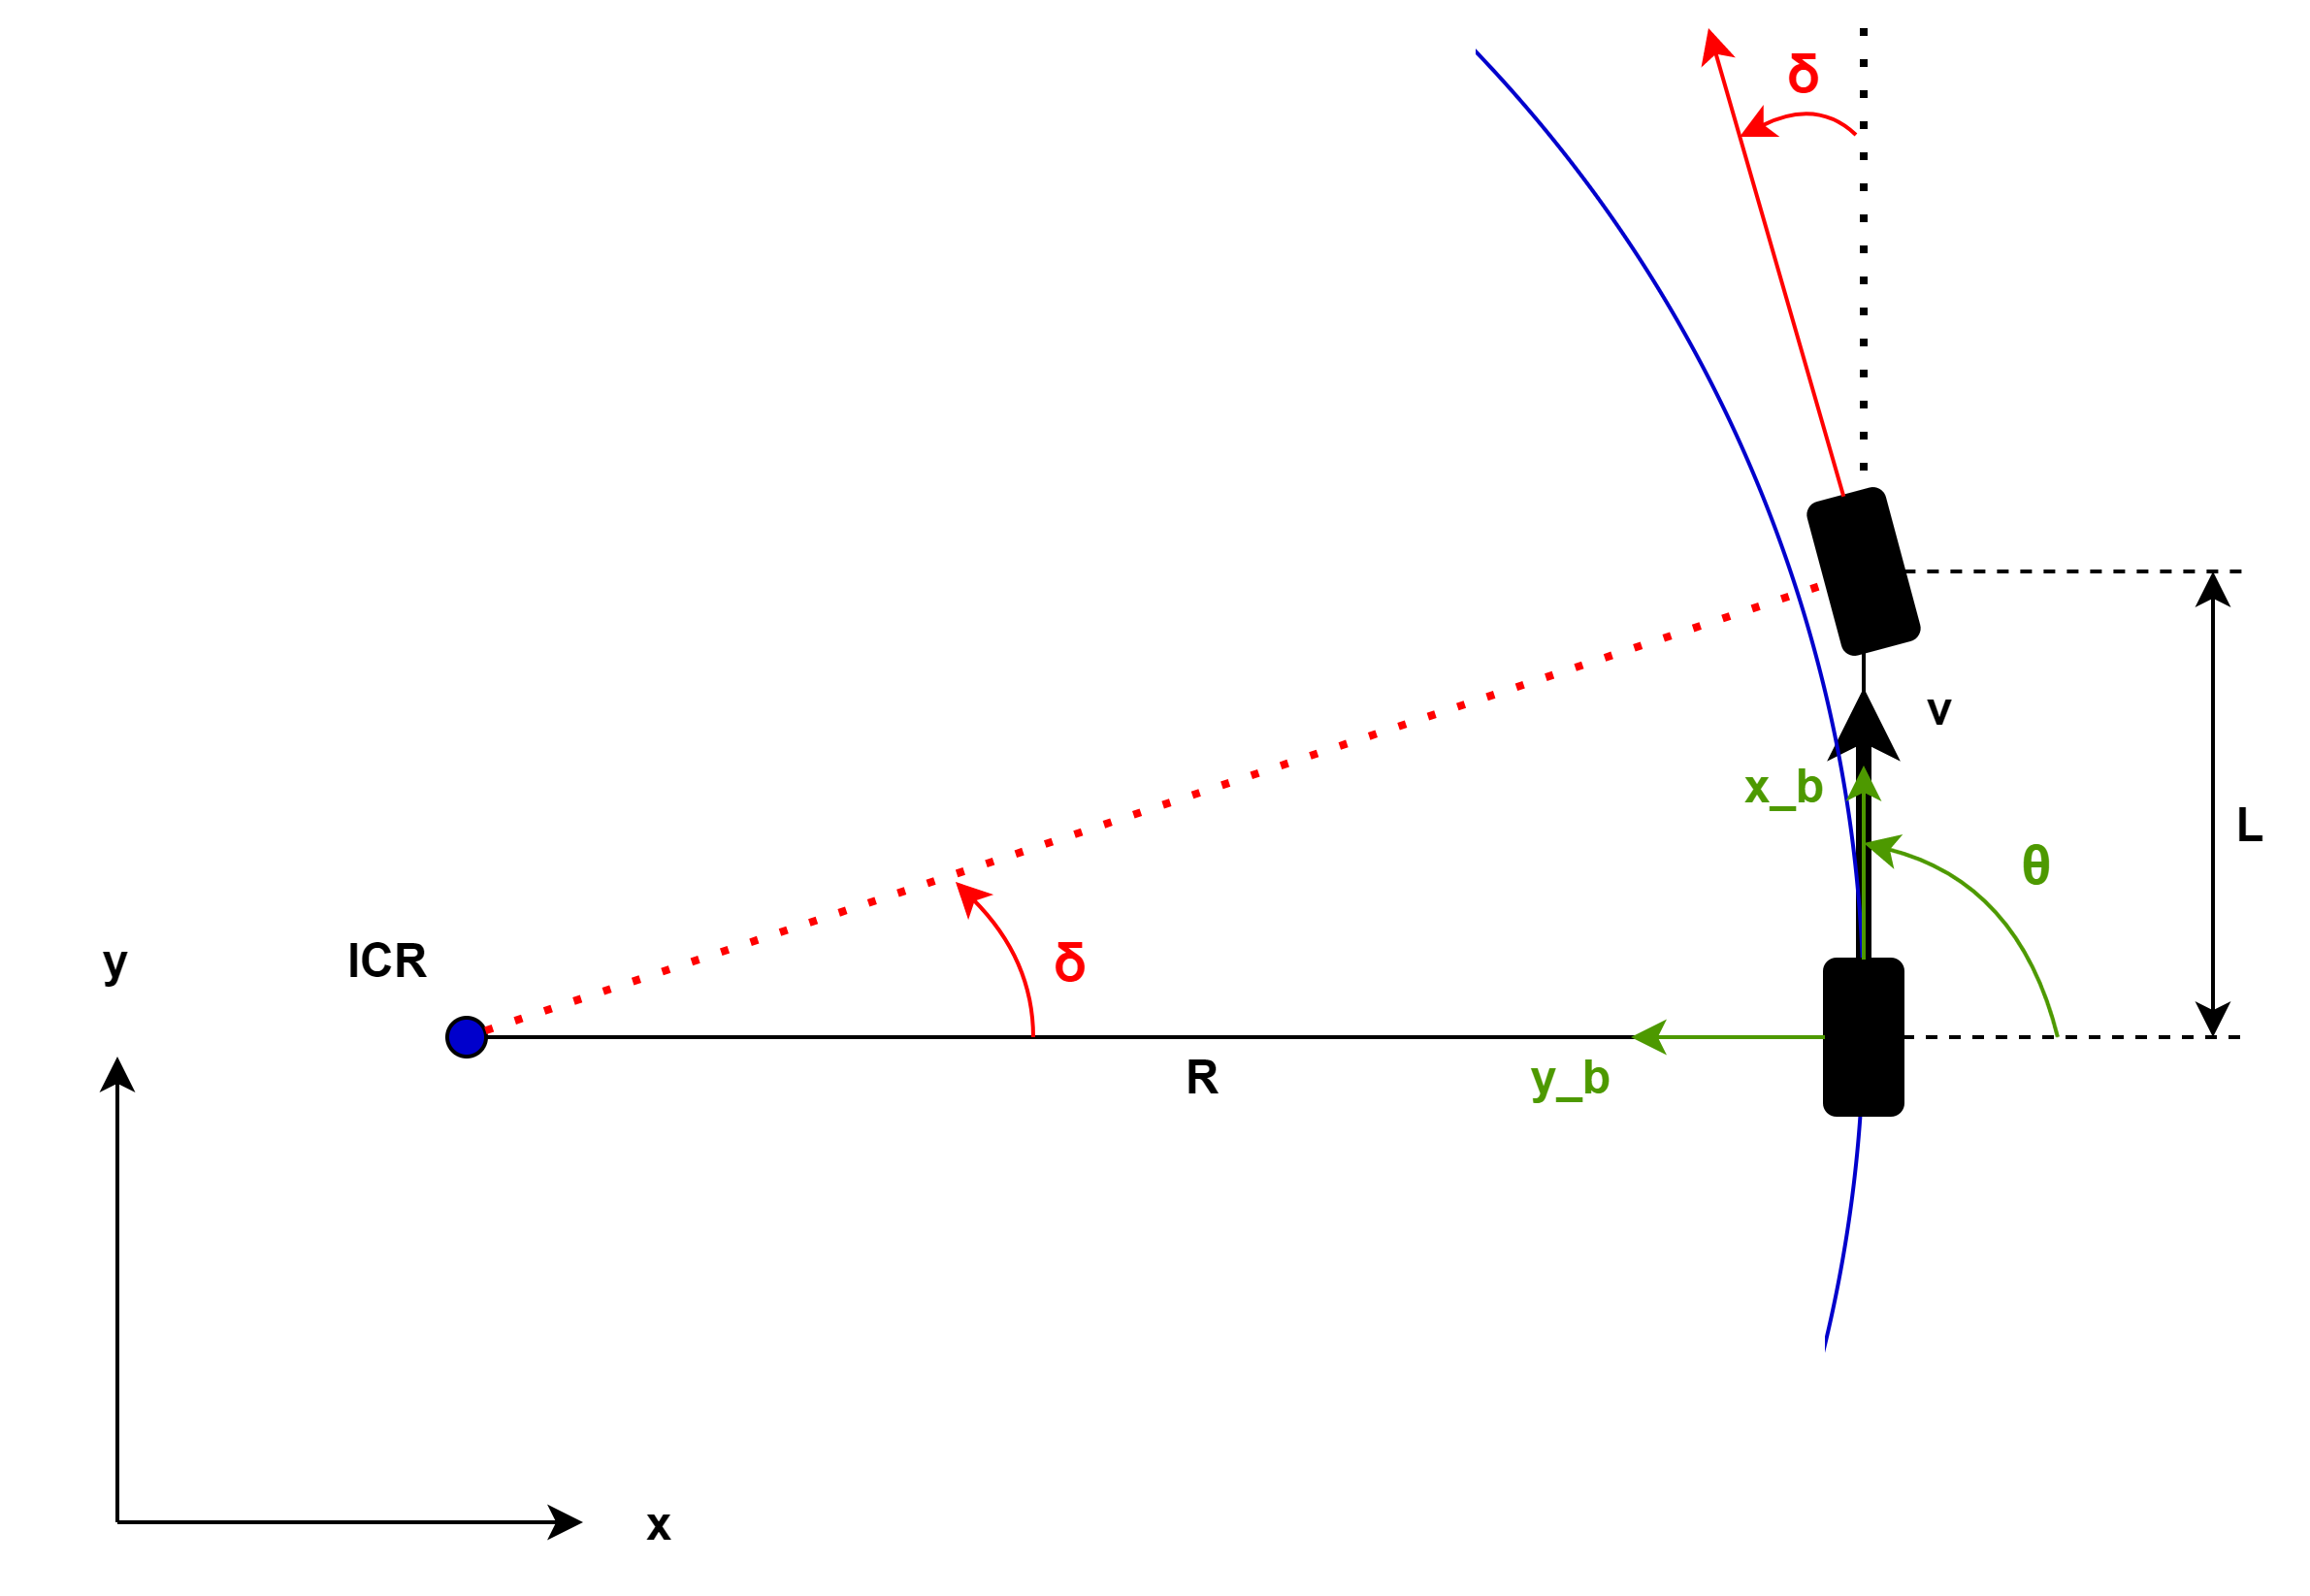

### Equations of motion

The origin of the body coordinate system moves along a circular path. The circle's center is the Instantaneous Center of Rotation (ICR) and has the radius $R$. Thus the eqations of motion are: 


$$\dot x = v \cos(\theta) \\
\dot y = v \sin(\theta) \\ 
\dot \theta = \frac{v}{L}tan(\gamma)$$


The maximum steering angle $\delta_{max}$  and the wheel base $L$ limit the radius $R$ or respectively the curvature $\kappa$:


$$R_{min} = \frac{L}{tan(\delta_{max})} \\
\kappa_{max} = \frac{1}{R_{min}}  = \frac{tan(\delta_{max})}{L} \\ 
$$


### References

[https://www.mathworks.com/help/robotics/ref/bicyclekinematicmodel.html](https://www.mathworks.com/help/robotics/ref/bicyclekinematicmodel.html)

Corke, Peter I. *Robotics, Vision and Control: Fundamental Algorithms in MATLAB*. Springer, 2011.

## Feasibility and Constraints

- Rubin Constraints

# ------------------------------------------

# Appendix I - Derivation of a minimum jerk trajectory

The trajectory generation for lane-changing is based on a minimum lateral jerk for the vehicle. The passenger comfort is often parametrized as the smoothness of the lane-changing maneuver, that is the third derivative of the lateral displacement. If the lateral displacement of the vehicle from the reference lane is specified by the variable $d(t)$ as in the Frenet Frame, then the lateral jerk is:


$$\dddot d(t)=\frac{d^3(d(t))}{dt^3}$$


Now let us minimize the squared sum of the lateral jerk along the vehicle's trajectory. The cost function $J$ to be minimized becomes:


$$J(d(t))=\frac{1}{2}\int _{t_i} ^{t_f} \dddot d(t)^2dt
$$


where $t_i
$ and $t_f$ are the starting time and the ending time of the trajectory. The constant $\frac{1}{2}$ in front is only for mathematical convenience otherwise it has no significance.

We assume that after changing its lane, the vehicle keeps driving on the new lane without any further movement. This way, we can set the boundary conditions at the beginning and at the end of the trajectory:


$$\dot d(t_i)=\dot d(t_f) =  \ddot d(t_i)=\ddot d(t_f)=0$$


Now we need to derive the order of the polynomial that resembles the trajectory.

## Calculus of the Variations

We refer to the technique called calculus of the variations to find the minimum of a functional. Please note that our cost function $J$ was also a function the lateral displacement over time $d\left(t\right)$, therefore we need to define a variation function that depends on time $\eta(t)$. Let us impose a similar set of boundary conditions for the variation, which means that it smoothly goes away at the boundaries, i.e., at the beginning and end of the trajectory:

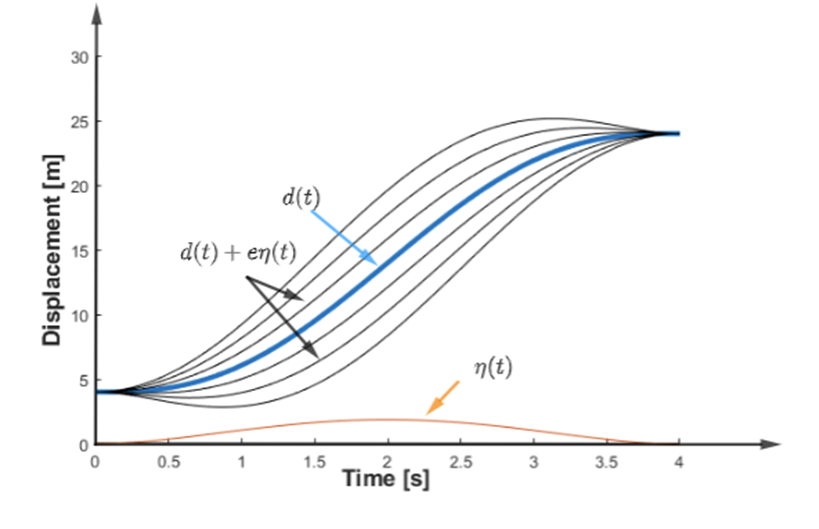


$$\eta(t_i)=\eta(t_f)=0
\\ \dot \eta(t_i)=\dot \eta(t_f)=0
\\ \ddot \eta(t_i)=\ddot \eta(t_f)=0$$


To minimize $J(d(t))$, we first replace $d(t)$by a variation $d(t)+\epsilon\eta(t)$ where $\varepsilon$ is a very small real number close to zero $d(t) \mapsto d(t)+\epsilon\eta(t)$:


$$J(d+e\eta)=\frac{1}{2}\int^{t_f}_{t_i}(\dddot d +e\dddot\eta)^2dt$$


We know that the functional $J$ has a minimum at $\epsilon =0$ and then we differentiate the cost function according to $\epsilon$ and replace it with zero.


$$ \frac{dJ(d+\epsilon\eta)}{\epsilon}=\int^{t_f}_{t_i}(\dddot d +e\dddot\eta)\dddot \eta dt
$$



$$\frac{dJ(d+\epsilon\eta)}{\epsilon} \big| _{\epsilon=0} =\int^{t_f}_{t_i}\dddot d\ \dddot\eta\ dt$$


Using integration by parts, we can rewrite this integral as:


$$\int ^{t_f}_{t_i}\dddot d \ \dddot \eta \ dt=  \dddot d \ \dddot \eta \big| ^{t_f}_{t_i} -\int^{t_f}_{t_i} \ddot \eta d^{(4)}dt=-\int ^{t_f}_{t_i} \ddot \eta d^{(4)}dt$$


Continuing the integration by parts:


$$\int ^{t_f}_{t_i} d^{(5)}  \dot \eta dt=   d^{(5)} \eta \big| ^{t_f}_{t_i} -\int ^{t_f}_{t_i}  \eta d^{(6)}dt=-\int ^{t_f}_{t_i}  \eta d^{(6)}dt$$


The final integral:


$$\frac{dJ(d+\epsilon \eta)}{\epsilon} \big |_{\epsilon=0}=-\int^{t_f}_{t_i}\eta d^{(6)}dt =0$$


The above property must hold true for any function $\eta(t)$, and therefore we have the fact that $d^{(6)}=0$, which means that function $d(t)$should have its sixth derivative equal to zero to have a minimum jerk function. $d(t)$has the general form of:


$$d(t)=a_0+a_1t+a_2t^2+a_3t^3+a_4t^4+a_5t^5$$


with the first and second derivatives, namely lateral speed and lateral acceleration as:


$$\dot d(t)=a_1+2a_2t+3a_3t^2+4a_4t^3+5a_5t^4$$



$$\ddot d(t)=2a_2+6a_3t+12a_4t^2+20a_5t^3$$


### Reference

Kyriakopoulos, K. J., & Saridis, G. N. (1991). Minimum jerk trajectory planning for robotic manipulators. *Cooperative Intelligent Robotics in Space*, *1387*, 159. https://doi.org/10.1117/12.25421